close all; clear all;
sfn_dir = '/home/alex/Dropbox/SfN/';
type = 'real';
plot_stuff = 1;
plot_controls = 0;file:///mnt/40086D4C086D41D0/Reverb_data/For_sorting/P08/config_dir/StandardConfig.m

dir_name = '/home/alex/Desktop/Kernels/Summary_data/';
names{1} = '/home/alex/Desktop/Kernels/Ronnie/P05/data/';
names{2} = '/home/alex/Desktop/Kernels/Ronnie/P06/data/';
names{3} = '/home/alex/Desktop/Kernels/Ronnie/P08/data/';
names{4} = '/home/alex/Desktop/Kernels/Ronnie/P13/data/';
names{5} = '/home/alex/Desktop/Kernels/Derry/P02/data/';
names{6} = '/home/alex/Desktop/Kernels/Derry/P03/data/';
names{7} = '/home/alex/Desktop/Kernels/Derry/P08/data/';
names{8} = '/home/alex/Desktop/Kernels/Kilkenny/P05/data/';
names{9} = '/home/alex/Desktop/Kernels/Kilkenny/P06/data/';
load('/mnt/40086D4C086D41D0/Reverb_data/coch.mat');
freqs = coch(1).params.f;  
num_pen = length(names);
for pen_no = 1:num_pen
    pen = names{pen_no};
    switch type
        case 'real'
            full_name = [pen,'/sep_kernel_adjbeta'];
            load(full_name);
            num_clusters = numel(sep_kernel);
            for clust = 1:num_clusters
                %anech
                params(pen_no).beta_anech(clust) = sep_kernel(clust).dexp_anech.beta;
                anech_kh = sep_kernel(clust).anech_k_h.k_h;
                params(pen_no).anech_kh(clust,:) = anech_kh;
                params(pen_no).ie_anech(clust) = sum(abs(min(anech_kh,0)))./sum(max(anech_kh,0));
                params(pen_no).i_anech(clust) = sum(abs(min(anech_kh,0)));
                params(pen_no).B_anech(clust) = sep_kernel(clust).dexp_anech.B;
                params(pen_no).CC_dexp_anech(clust) = sep_kernel(clust).CC_dexp_anech;
                params(pen_no).CC_anech(clust) = sep_kernel(clust).CC_anech;
                params(pen_no).RMSE_anech(clust) = sep_kernel(clust).RMSE_anech;
                params(pen_no).RMSE_dexp_anech(clust) = sep_kernel(clust).RMSE_dexp_anech;
                %reverb1
                params(pen_no).beta_small(clust) = sep_kernel(clust).dexp_reverb1.beta;
                reverb1_kh = sep_kernel(clust).reverb1_k_h.k_h;
                params(pen_no).reverb1_kh(clust,:) = reverb1_kh;
                params(pen_no).ie_reverb1(clust) = sum(abs(min(reverb1_kh,0)))./sum(max(reverb1_kh,0));
                params(pen_no).i_reverb1(clust) = sum(abs(min(reverb1_kh,0)));
                params(pen_no).B_reverb1(clust) = sep_kernel(clust).dexp_reverb1.B;
                params(pen_no).CC_dexp_reverb1(clust) = sep_kernel(clust).CC_dexp_reverb1;
                params(pen_no).CC_reverb1(clust) = sep_kernel(clust).CC_reverb1;
                params(pen_no).RMSE_reverb1(clust) = sep_kernel(clust).RMSE_reverb1;
                params(pen_no).RMSE_dexp_reverb1(clust) = sep_kernel(clust).RMSE_dexp_reverb1;
                %reverb2
                params(pen_no).beta_big(clust) = sep_kernel(clust).dexp_reverb2.beta;
                reverb2_kh = sep_kernel(clust).reverb2_k_h.k_h;
                params(pen_no).reverb2_kh(clust,:) = reverb2_kh;
                params(pen_no).ie_reverb2(clust) = sum(abs(min(reverb2_kh,0)))./sum(max(reverb2_kh,0));
                params(pen_no).i_reverb2(clust) = sum(abs(min(reverb2_kh,0)));
                params(pen_no).B_reverb2(clust) = sep_kernel(clust).dexp_reverb2.B;
                params(pen_no).CC_dexp_reverb2(clust) = sep_kernel(clust).CC_dexp_reverb2;
                params(pen_no).CC_reverb2(clust) = sep_kernel(clust).CC_reverb2;
                params(pen_no).RMSE_reverb2(clust) = sep_kernel(clust).RMSE_reverb2;
                params(pen_no).RMSE_dexp_reverb2(clust) = sep_kernel(clust).RMSE_dexp_reverb2;
                %general
                params(pen_no).NPSP(clust) = sep_kernel(clust).NPSP;
                params(pen_no).k_f(clust,:) = sep_kernel(clust).full_kernel.k_f;
                [~,ix] = max(sep_kernel(clust).full_kernel.k_f);
                params(pen_no).bf(clust) = freqs(ix);
            end
        case 'model'
            full_name = [pen,'/model_adjbeta'];
            load(full_name);
            num_clusters = numel(model_kernel);
            for clust = 1:num_clusters
                %anech
                params(pen_no).beta_anech(clust) = model_kernel(clust).dexp_anech.beta;
                anech_kh = model_kernel(clust).k_h_model_anech.k_h;
                params(pen_no).anech_kh(clust,:) = anech_kh;
                params(pen_no).ie_anech(clust) = sum(abs(min(anech_kh,0)))./sum(max(anech_kh,0));
                params(pen_no).i_anech(clust) = sum(abs(min(anech_kh,0)));
                params(pen_no).B_anech(clust) = model_kernel(clust).dexp_anech.B;
                %reverb1
                params(pen_no).beta_small(clust) = model_kernel(clust).dexp_reverb1.beta;
                reverb1_kh = model_kernel(clust).k_h_model_reverb1.k_h;
                flp_reverb1_kh = flipud(reverb1_kh);
                [~,max_ix_r1] = max(flp_reverb1_kh);
                flp_reverb1_kh = flp_reverb1_kh(max_ix_r1:end);
                params(pen_no).reverb1_kh(clust,:) = reverb1_kh;
                params(pen_no).ie_reverb1(clust) = sum(abs(min(reverb1_kh,0)))./sum(max(reverb1_kh,0));
                params(pen_no).i_reverb1(clust) = sum(abs(min(reverb1_kh,0)));
                params(pen_no).B_reverb1(clust) = model_kernel(clust).dexp_reverb1.B;
                %reverb2
                params(pen_no).beta_big(clust) = model_kernel(clust).dexp_reverb2.beta;
                reverb2_kh = model_kernel(clust).k_h_model_reverb2.k_h;
                params(pen_no).reverb2_kh(clust,:) = reverb2_kh;
                params(pen_no).ie_reverb2(clust) = sum(abs(min(reverb2_kh,0)))./sum(max(reverb2_kh,0));
                params(pen_no).i_reverb2(clust) = sum(abs(min(reverb2_kh,0)));
                flp_reverb2_kh = flipud(reverb2_kh);
                [~,max_ix_r2] = max(flp_reverb2_kh);
                flp_reverb2_kh = flp_reverb2_kh(max_ix_r2:end);
                kh_r1_r2 = [flp_reverb1_kh;flp_reverb2_kh];
                F_r1_r2 = [model_kernel(clust).dexp_reverb1.F';model_kernel(clust).dexp_reverb2.F'];
                [R,P] = corrcoef(F_r1_r2,kh_r1_r2);
                params(pen_no).CC_dexp_r(clust) = R(2,1);
                params(pen_no).CC_dexp_pval(clust) = P(2,1);
                params(pen_no).B_reverb2(clust) = model_kernel(clust).dexp_reverb2.B;
                params(pen_no).NPSP(clust) = model_kernel(clust).NPSP;
                params(pen_no).k_f(clust,:) = model_kernel(clust).full_kernel_model.k_f;
                [~,ix] = max(model_kernel(clust).full_kernel_model.k_f);
                params(pen_no).bf(clust) = freqs(ix);
            end
    end
    params(pen_no).ratio_big_small = params(pen_no).beta_big./params(pen_no).beta_small;
    params(pen_no).diff_big_small = params(pen_no).beta_big - params(pen_no).beta_small;
    params(pen_no).per_big_small = 100.*((params(pen_no).beta_big - params(pen_no).beta_small)./params(pen_no).beta_small);
    params(pen_no).ratio_adj_big_small = (params(pen_no).beta_big - params(pen_no).beta_small)./(params(pen_no).beta_big + params(pen_no).beta_small);
    params(pen_no).pen_name = pen;
end

Plot the I/E ratio versus BF

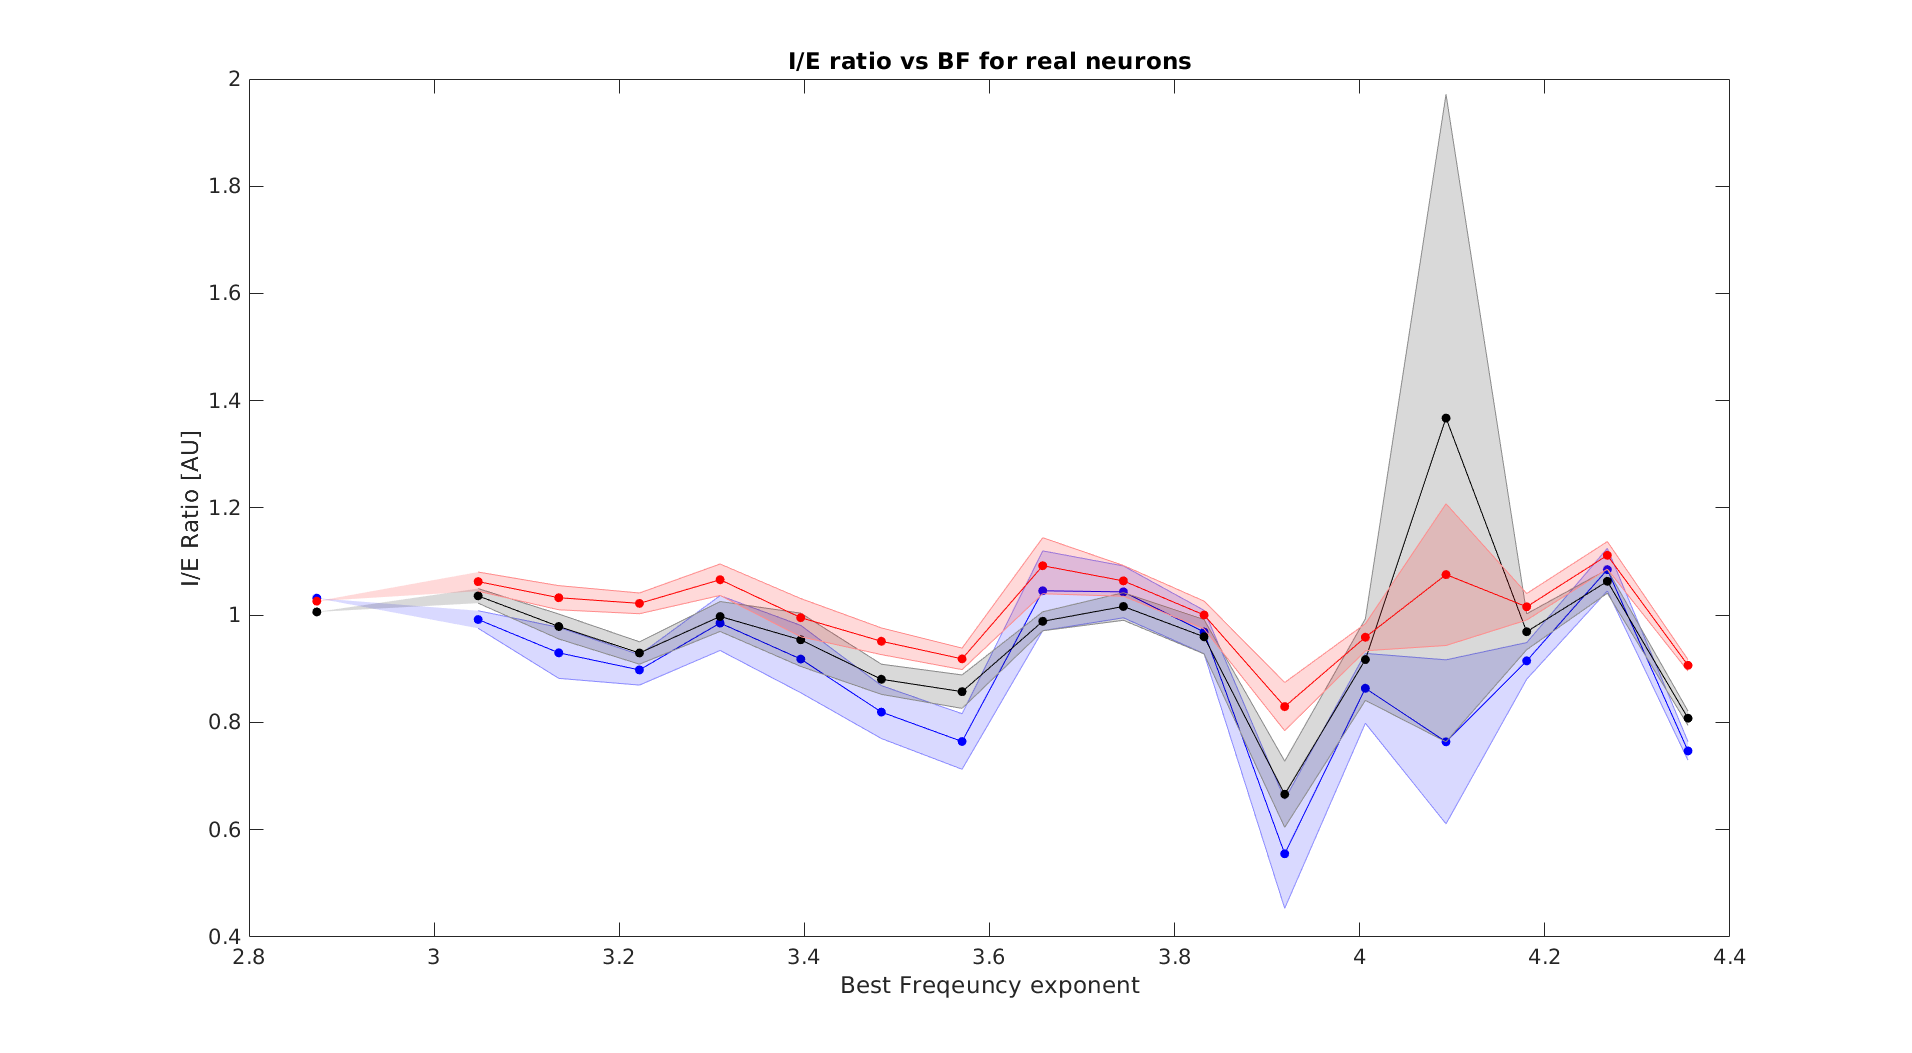

if plot_stuff
    BF = reach(params,'bf');
    ie_anech_all = reach(params,'ie_anech');
    ie_reverb1_all = reach(params,'ie_reverb1');
    ie_reverb2_all = reach(params,'ie_reverb2');
    
    for jj = 1:numel(freqs)
        ie_anech_sort{jj} = ie_anech_all(BF==freqs(jj));
        ie_reverb1_sort{jj} = ie_reverb1_all(BF==freqs(jj));
        ie_reverb2_sort{jj} = ie_reverb2_all(BF==freqs(jj));
    end
    freq_plot = freqs./1000;
    figure('units','normalized','outerposition',[0 0 1 1]);
    shadedErrorBar(log10(freqs),cellfun(@nanmean,ie_anech_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),ie_anech_sort,'UniformOutput',false)),{'b-o','markerfacecolor','b'},1); hold on;
    shadedErrorBar(log10(freqs),cellfun(@nanmean,ie_reverb1_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),ie_reverb1_sort,'UniformOutput',false)),{'k-o','markerfacecolor','k'},1);
    shadedErrorBar(log10(freqs),cellfun(@nanmean,ie_reverb2_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),ie_reverb2_sort,'UniformOutput',false)),{'r-o','markerfacecolor','r'},1);
    % legend('Anechoic','Small','Big');
    %  xticks([1:spacing:numel(freqs)]);
    % xticklabels(freqs([1:spacing:numel(freqs)]));
    xlabel('Best Freqeuncy exponent');
    ylabel('I/E Ratio [AU]');
    title(['I/E ratio vs BF for ',type,' neurons']);
    set(0,'defaultAxesFontSize',16);
    save_name = [dir_name,type,'_neurons_all_data_I_E_ratio_vs_BF.png'];
    export_fig(save_name);
end

Plot the I vs BF

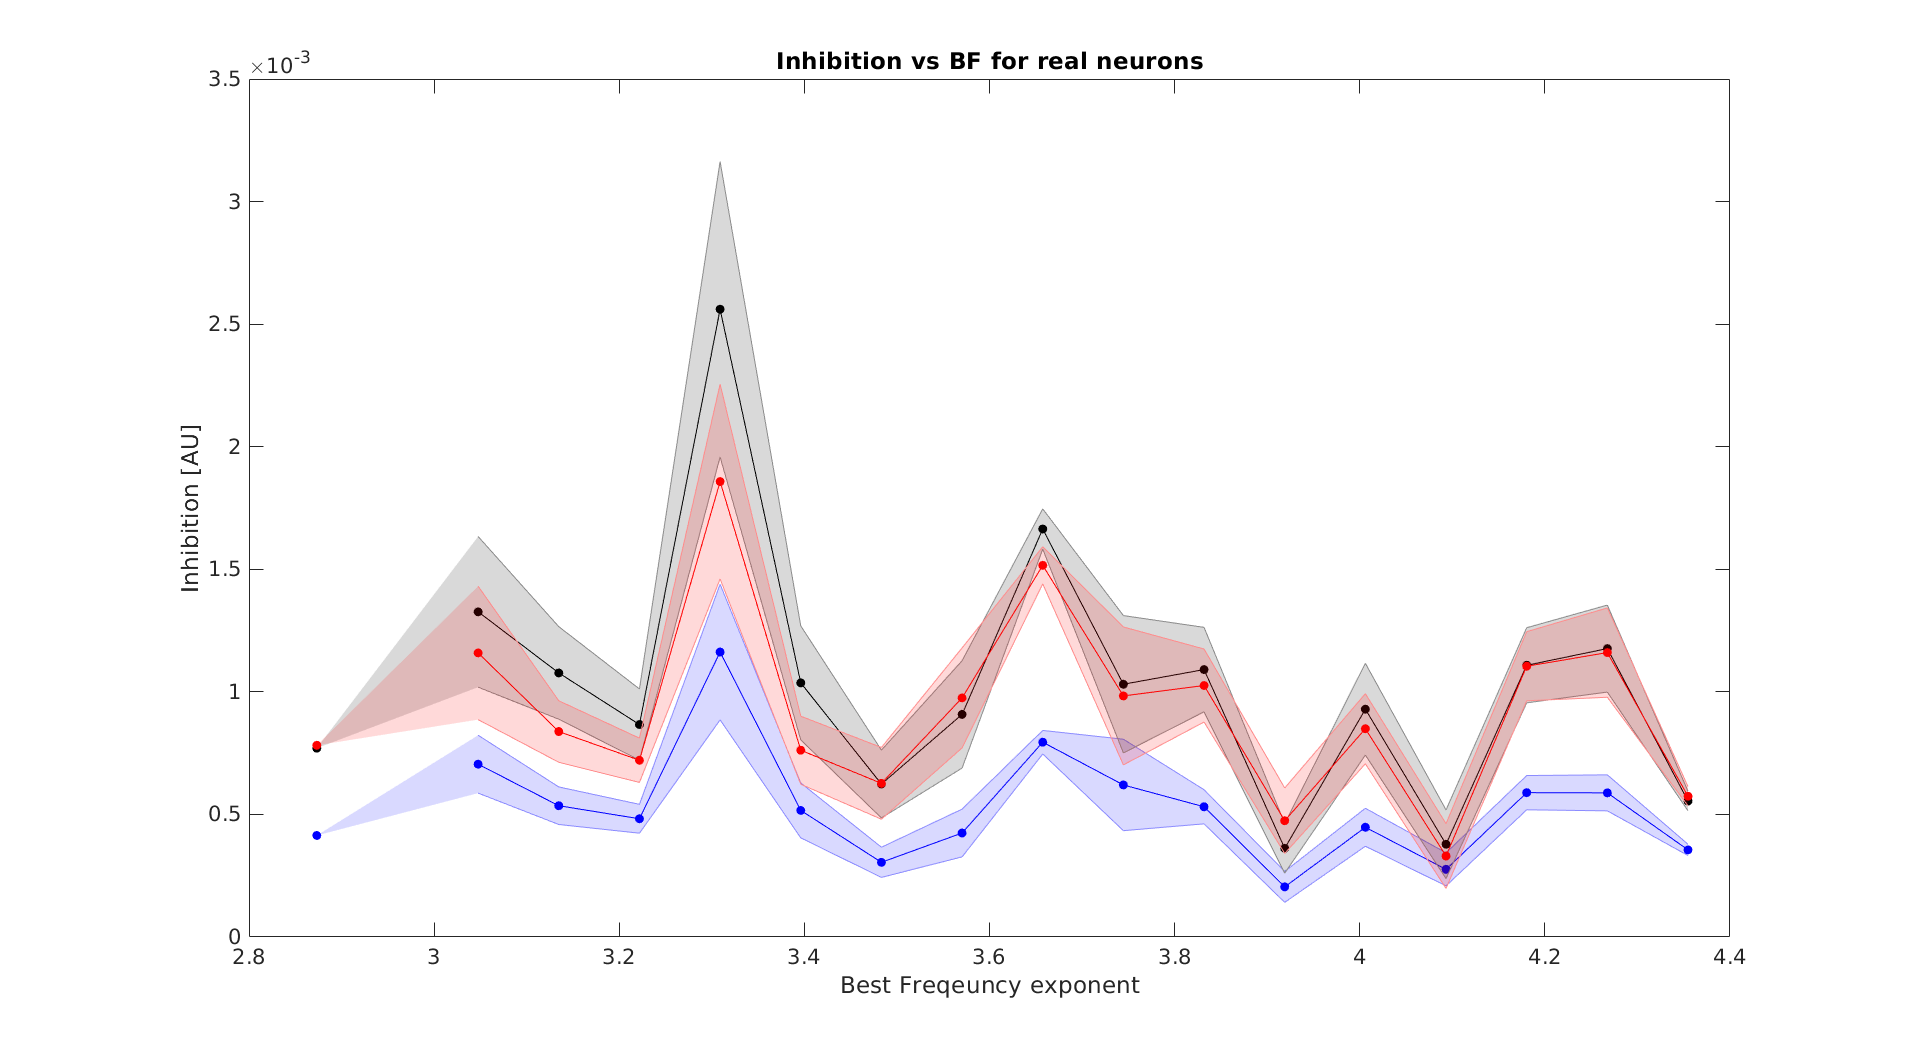

if plot_stuff
    BF = reach(params,'bf');
    i_anech_all = reach(params,'i_anech');
    i_reverb1_all = reach(params,'i_reverb1');
    i_reverb2_all = reach(params,'i_reverb2');
    
    for jj = 1:numel(freqs)
        i_anech_sort{jj} = i_anech_all(BF==freqs(jj));
        i_reverb1_sort{jj} = i_reverb1_all(BF==freqs(jj));
        i_reverb2_sort{jj} = i_reverb2_all(BF==freqs(jj));
    end
    freq_plot = freqs./1000;
    figure('units','normalized','outerposition',[0 0 1 1]);
    shadedErrorBar(log10(freqs),cellfun(@nanmean,i_anech_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),i_anech_sort,'UniformOutput',false)),{'b-o','markerfacecolor','b'},1); hold on;
    shadedErrorBar(log10(freqs),cellfun(@nanmean,i_reverb1_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),i_reverb1_sort,'UniformOutput',false)),{'k-o','markerfacecolor','k'},1);
    shadedErrorBar(log10(freqs),cellfun(@nanmean,i_reverb2_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),i_reverb2_sort,'UniformOutput',false)),{'r-o','markerfacecolor','r'},1);
    % legend('Anechoic','Small','Big');
    %  xticks([1:spacing:numel(freqs)]);
    % xticklabels(freqs([1:spacing:numel(freqs)]));
    xlabel('Best Freqeuncy exponent');
    ylabel('Inhibition [AU]');
    title(['Inhibition vs BF for ',type,' neurons']);
    set(0,'defaultAxesFontSize',16);
    save_name = [dir_name,type,'_neurons_all_data_I_vs_BF.png'];
    export_fig(save_name);
end

Plot the B versus BF

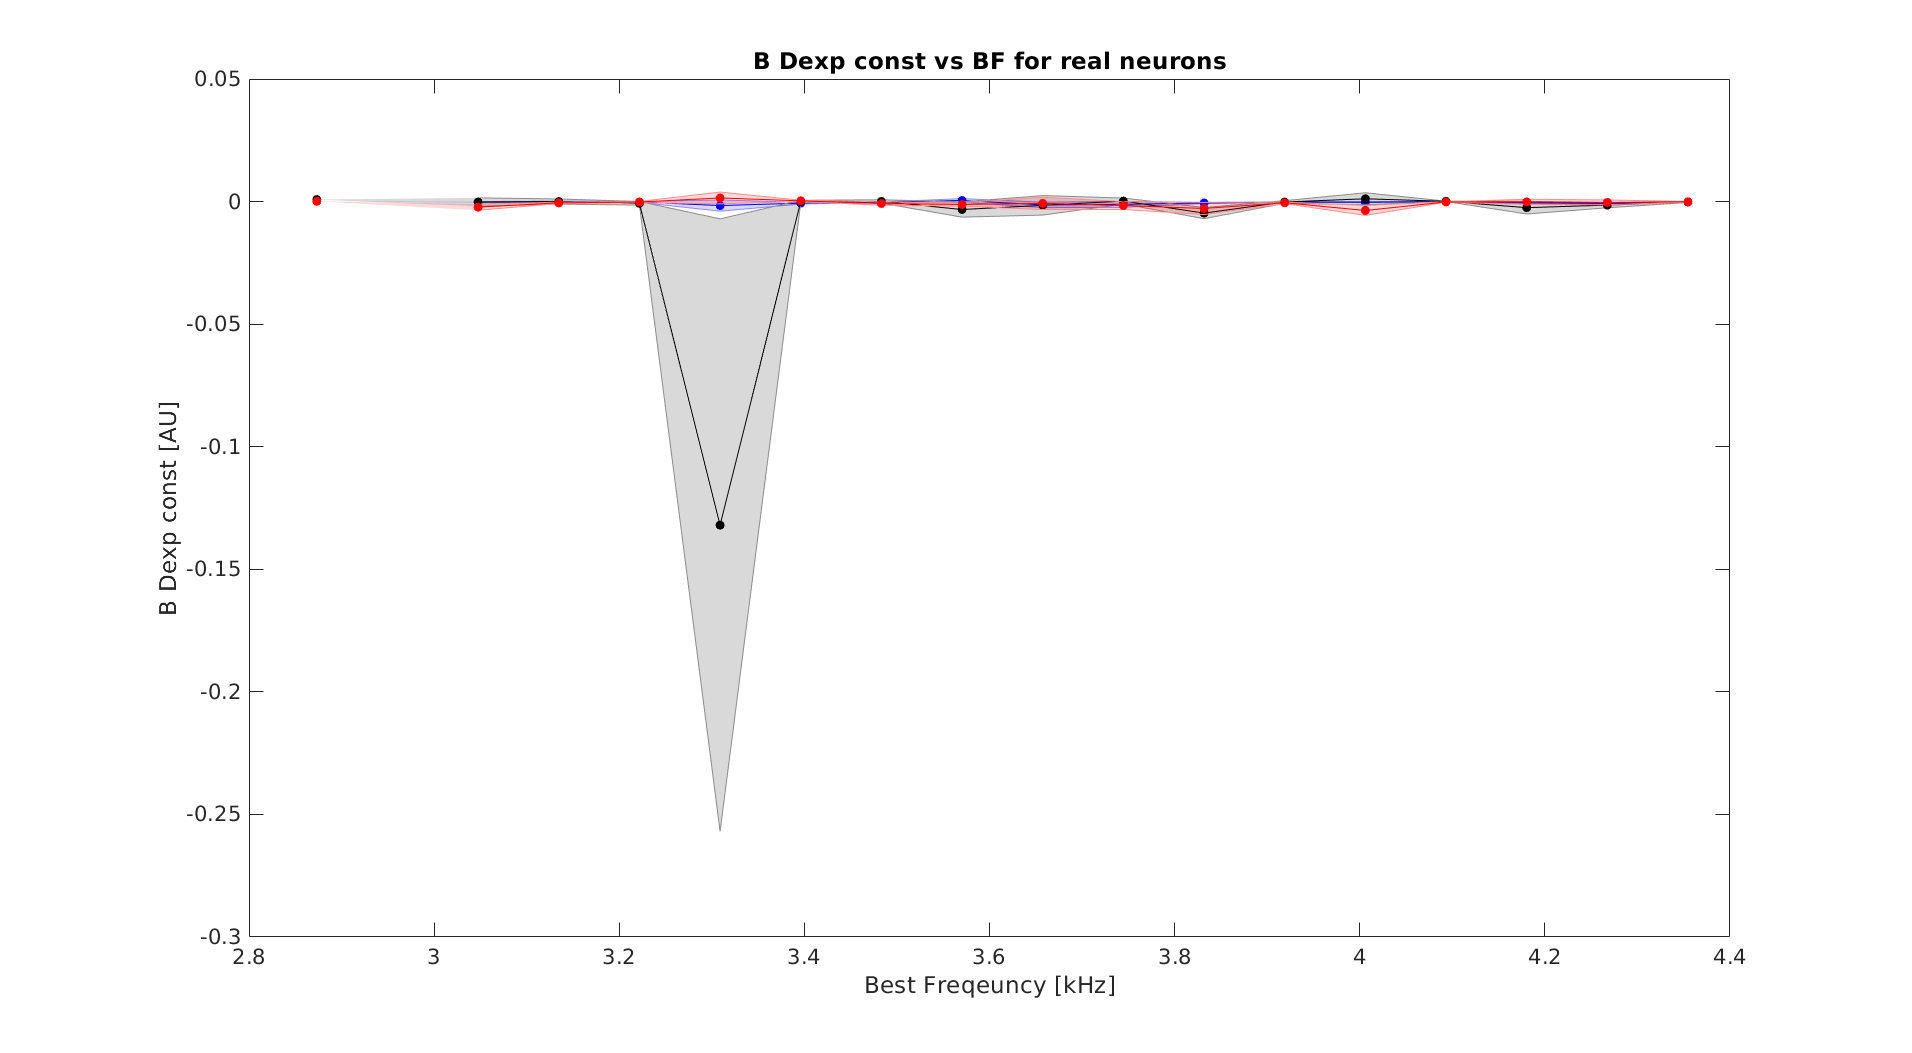

if plot_stuff
    B_anech_all = reach(params,'B_anech');
    B_reverb1_all = reach(params,'B_reverb1');
    B_reverb2_all = reach(params,'B_reverb2');
    
    for jj = 1:numel(freqs)
        B_anech_sort{jj} = B_anech_all(BF==freqs(jj));
        B_reverb1_sort{jj} = B_reverb1_all(BF==freqs(jj));
        B_reverb2_sort{jj} = B_reverb2_all(BF==freqs(jj));
    end
    freq_plot = freqs./1000;
    figure('units','normalized','outerposition',[0 0 1 1]);
    shadedErrorBar(log10(freqs),cellfun(@nanmean,B_anech_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),B_anech_sort,'UniformOutput',false)),{'b-o','markerfacecolor','b'},1); hold on;
    shadedErrorBar(log10(freqs),cellfun(@nanmean,B_reverb1_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),B_reverb1_sort,'UniformOutput',false)),{'k-o','markerfacecolor','k'},1);
    shadedErrorBar(log10(freqs),cellfun(@nanmean,B_reverb2_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),B_reverb2_sort,'UniformOutput',false)),{'r-o','markerfacecolor','r'},1);
    % legend('Anechoic','Small','Big');
    %  xticks([1:spacing:numel(freqs)]);
    % xticklabels(freqs([1:spacing:numel(freqs)]));
    xlabel('Best Freqeuncy [kHz]');
    ylabel('B Dexp const [AU]');
    title(['B Dexp const vs BF for ',type,' neurons']);
    set(0,'defaultAxesFontSize',16);
    save_name = [dir_name,type,'_neurons_all_data_B_const_vs_BF.png'];
    export_fig(save_name);
end

Plot the beta versus BF

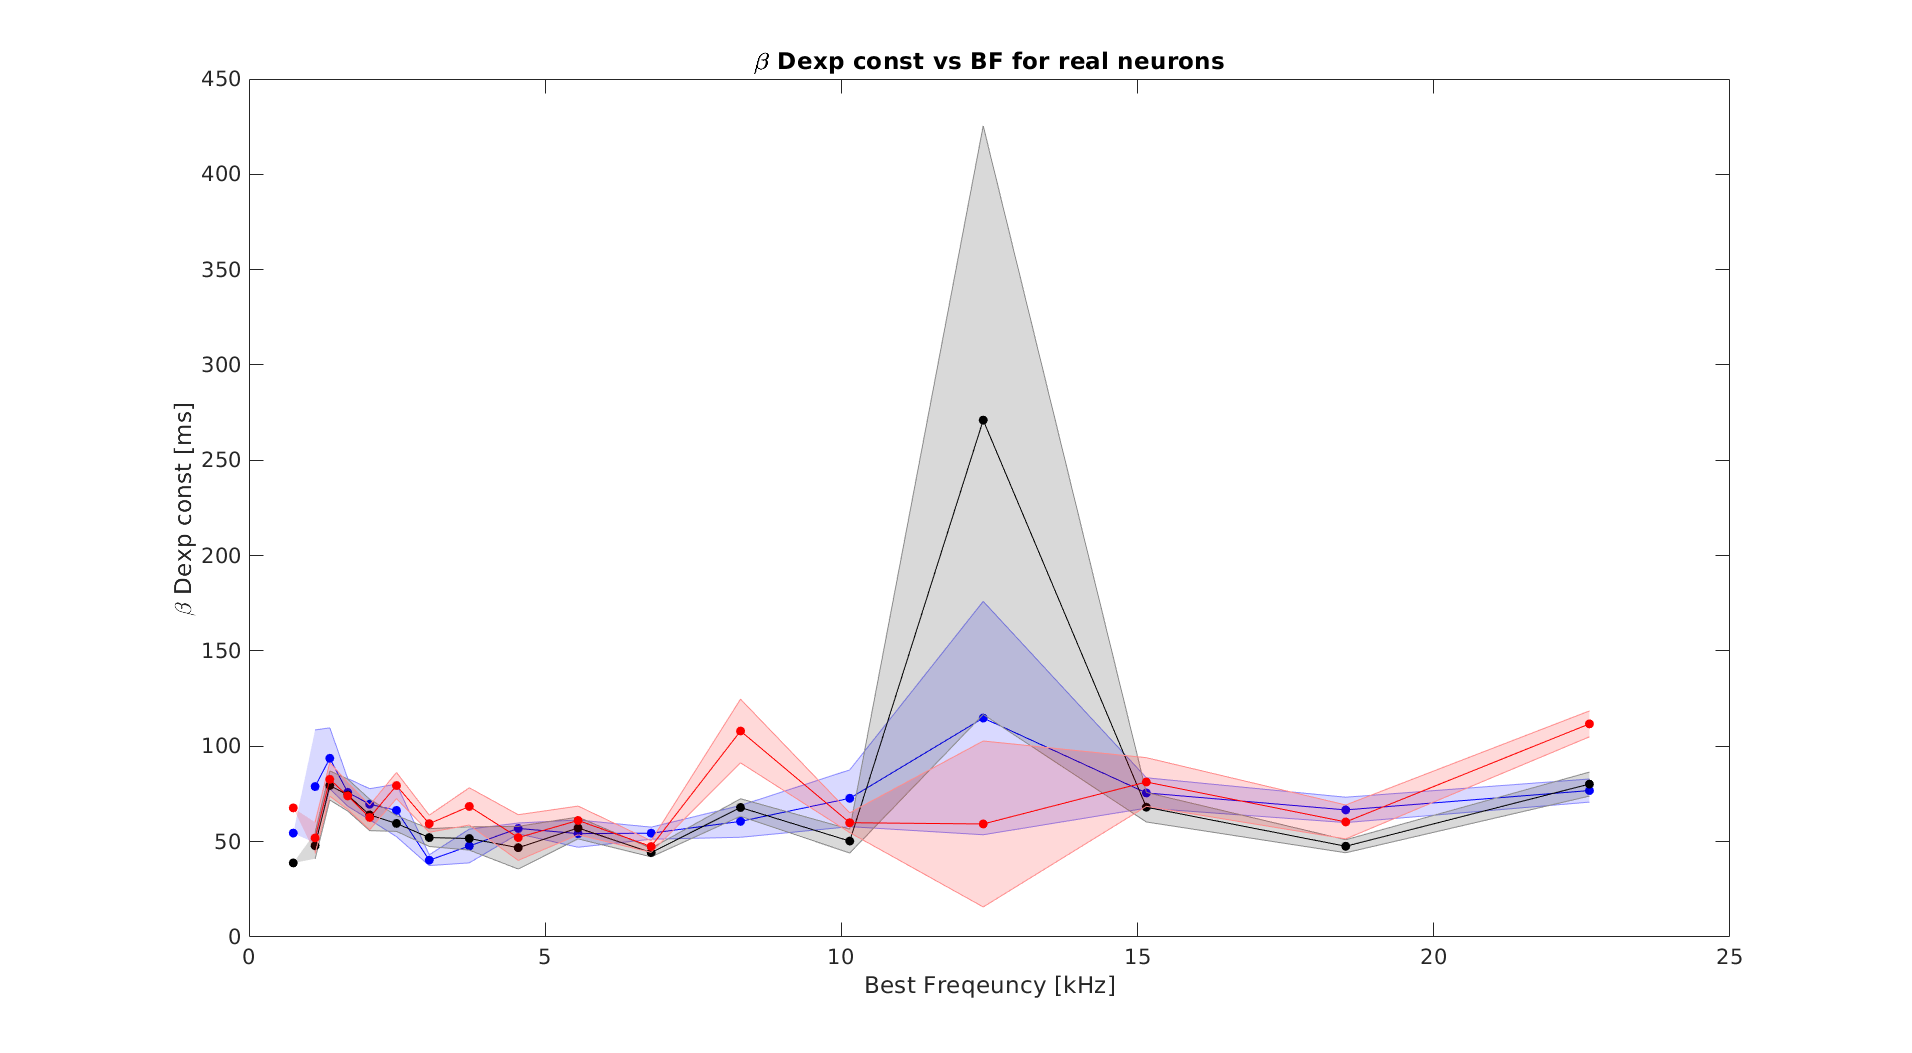

if plot_stuff
    beta_anech_all = reach(params,'beta_anech');
    beta_reverb1_all = reach(params,'beta_small');
    beta_reverb2_all = reach(params,'beta_big');
    
    for jj = 1:numel(freqs)
        beta_anech_sort{jj} = beta_anech_all(BF==freqs(jj));
        beta_reverb1_sort{jj} = beta_reverb1_all(BF==freqs(jj));
        beta_reverb2_sort{jj} = beta_reverb2_all(BF==freqs(jj));
    end
    freq_plot = freqs./1000;
    figure('units','normalized','outerposition',[0 0 1 1]);
    shadedErrorBar(freq_plot,cellfun(@nanmean,beta_anech_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),beta_anech_sort,'UniformOutput',false)),{'b-o','markerfacecolor','b'},1); hold on;
    shadedErrorBar(freq_plot,cellfun(@nanmean,beta_reverb1_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),beta_reverb1_sort,'UniformOutput',false)),{'k-o','markerfacecolor','k'},1);
    shadedErrorBar(freq_plot,cellfun(@nanmean,beta_reverb2_sort),cell2mat(cellfun(@(x) std(x)./sqrt(numel(x)),beta_reverb2_sort,'UniformOutput',false)),{'r-o','markerfacecolor','r'},1);
    % legend('Anechoic','Small','Big');
    %  xticks([1:spacing:numel(freqs)]);
    % xticklabels(freqs([1:spacing:numel(freqs)]));
    xlabel('Best Freqeuncy [kHz]');
    ylabel('\beta Dexp const [ms]');
    title(['\beta Dexp const vs BF for ',type,' neurons']);
    set(0,'defaultAxesFontSize',16);
    save_name = [dir_name,type,'_neurons_all_data_beta_const_vs_BF.png'];
    export_fig(save_name);
end

Make a bar plot for the Bs in the three different conditions

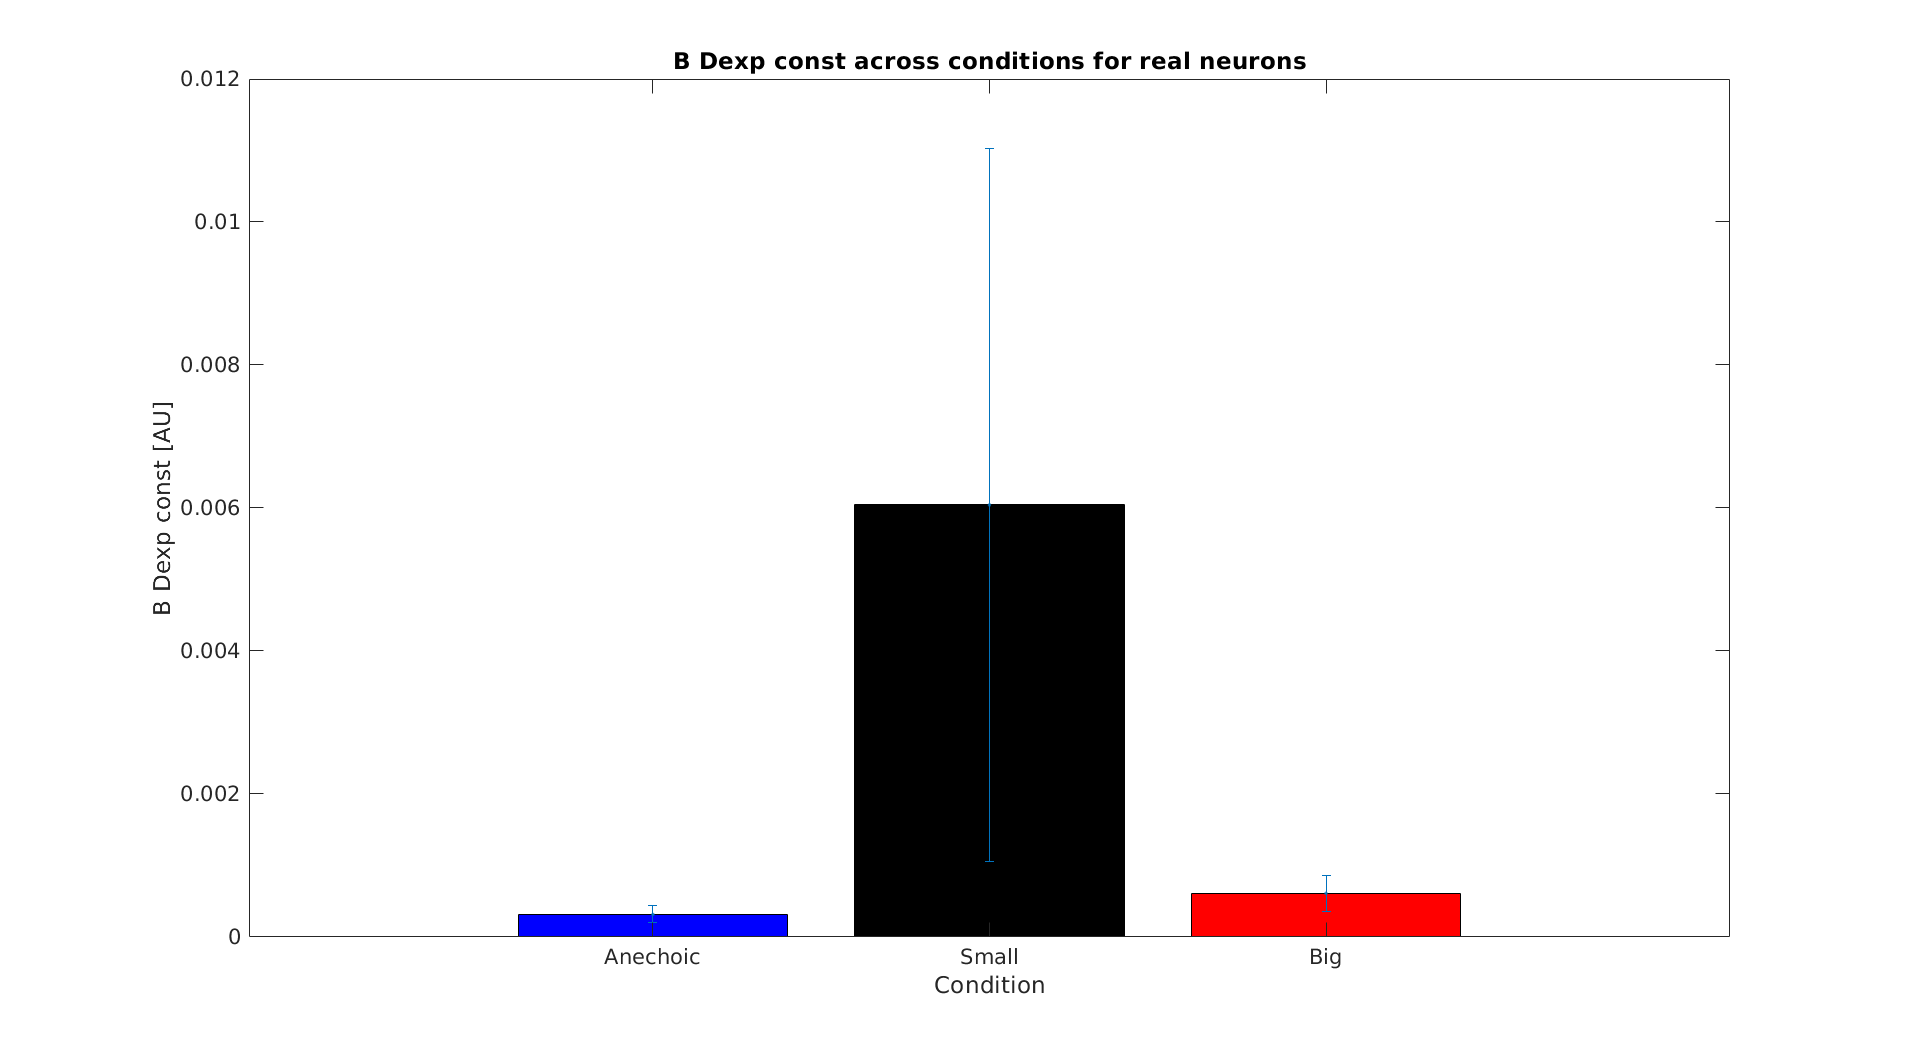

u_anech_B = abs(mean(B_anech_all));
u_reverb1_B = abs(mean(B_reverb1_all));
u_reverb2_B = abs(mean(B_reverb2_all));
sz = length(B_anech_all);
sqrt_n = sqrt(sz);
sem_anech_B = std(B_anech_all)./sqrt_n;
sem_reverb1_B = std(B_reverb1_all)./sqrt_n;
sem_reverb2_B = std(B_reverb2_all)./sqrt_n;
figure('units','normalized','outerposition',[0 0 1 1]);
bar(1,u_anech_B,'b');hold on;
bar(2,u_reverb1_B,'k');
bar(3,u_reverb2_B,'r');
errorbar([1 2 3],[u_anech_B u_reverb1_B u_reverb2_B],[sem_anech_B sem_reverb1_B sem_reverb2_B],'.');
xticks([1:3]);
xticklabels({'Anechoic','Small','Big'});
xlabel('Condition');
ylabel('B Dexp const [AU]');
title(['B Dexp const across conditions for ',type,' neurons']);
set(0,'defaultAxesFontSize',16);
save_name = [dir_name,type,'_neurons_all_data_B_const_across_conditions.png'];
export_fig(save_name);

Make a bar plot for the I/E in the three different conditions

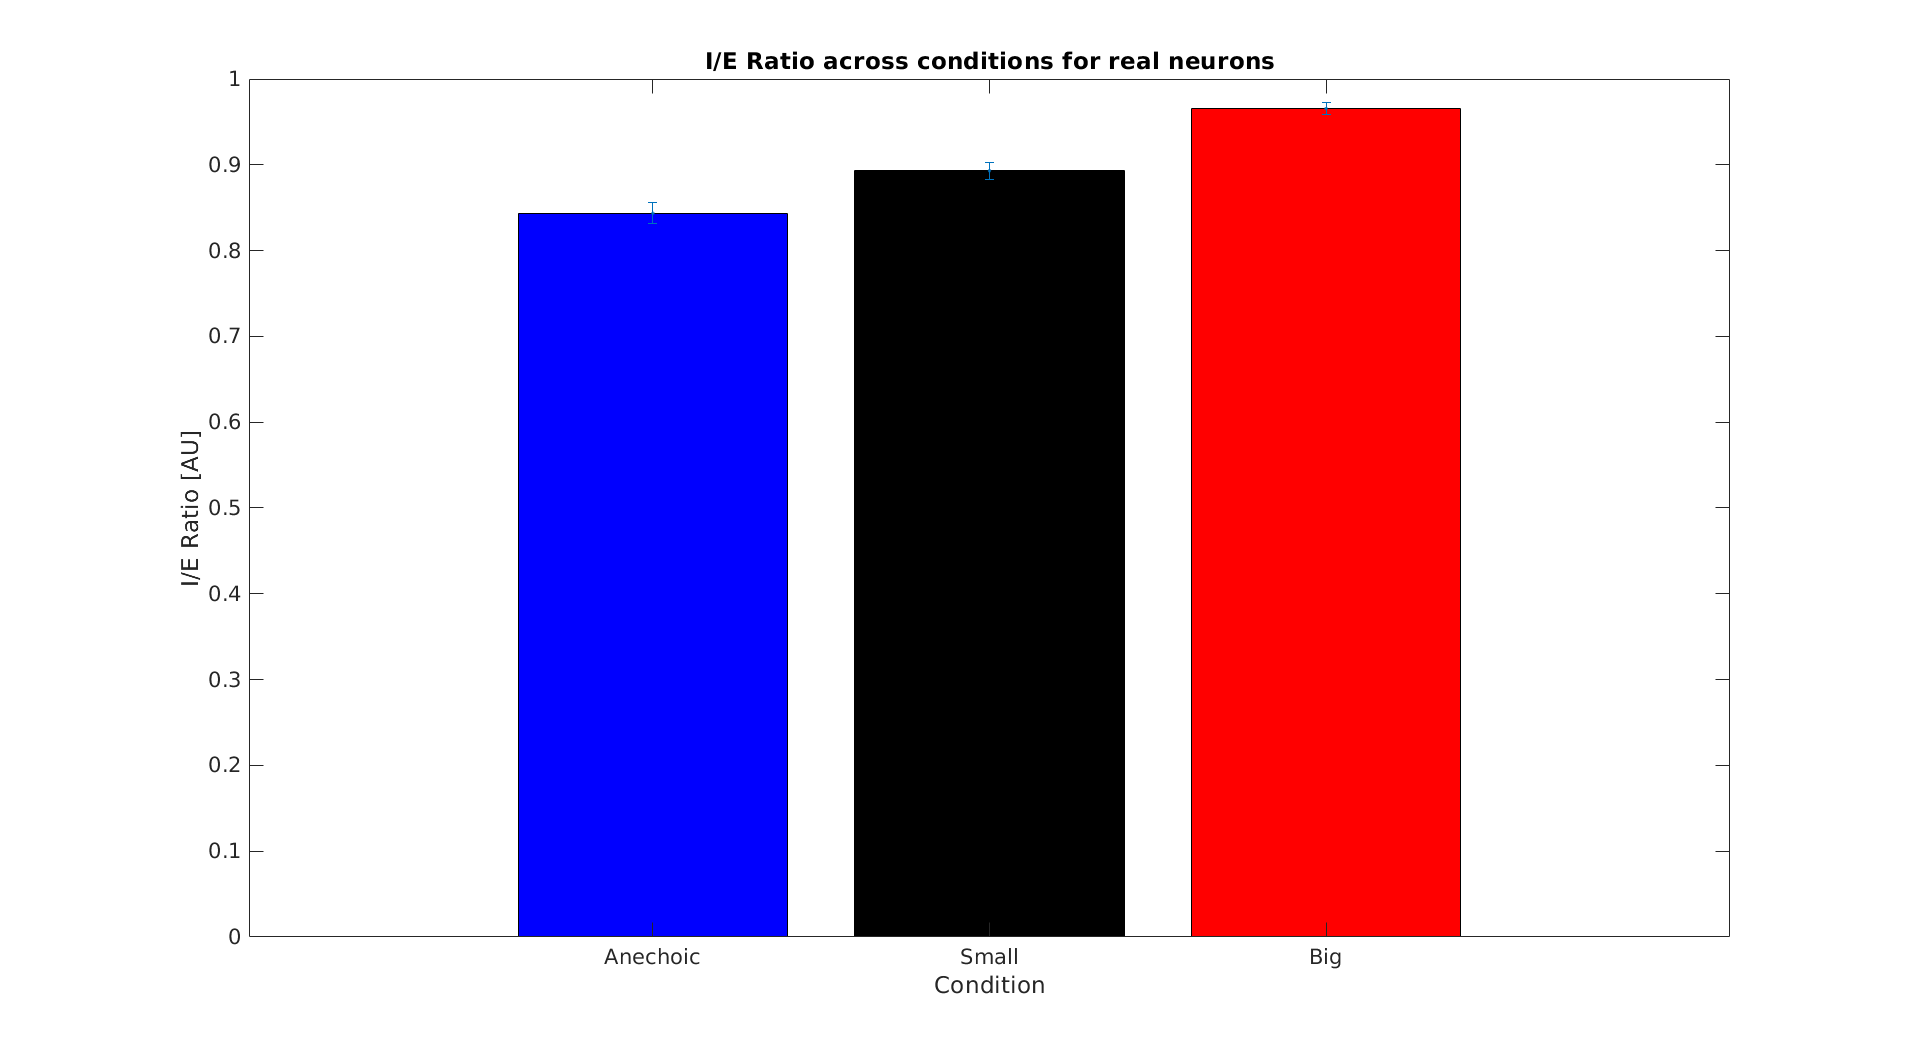

u_anech_ie = mean(ie_anech_all);
u_reverb1_ie = mean(ie_reverb1_all);
u_reverb2_ie = mean(ie_reverb2_all);
sz = length(ie_anech_all);
sqrt_n = sqrt(sz);
sem_anech_ie = std(ie_anech_all)./sqrt_n;
sem_reverb1_ie = std(ie_reverb1_all)./sqrt_n;
sem_reverb2_ie = std(ie_reverb2_all)./sqrt_n;
figure('units','normalized','outerposition',[0 0 1 1]);
bar(1,u_anech_ie,'b');hold on;
bar(2,u_reverb1_ie,'k');
bar(3,u_reverb2_ie,'r');
errorbar([1 2 3],[u_anech_ie u_reverb1_ie u_reverb2_ie],[sem_anech_ie sem_reverb1_ie sem_reverb2_ie],'.');
xticks([1:3]);
xticklabels({'Anechoic','Small','Big'});
xlabel('Condition');
ylabel('I/E Ratio [AU]');
title(['I/E Ratio across conditions for ',type,' neurons']);
set(0,'defaultAxesFontSize',16);
save_name = [dir_name,type,'_neurons_all_data_I_E_Ratio_across_conditions.png'];
export_fig(save_name);

Make a bar plot for the Inhibition in the three different conditions

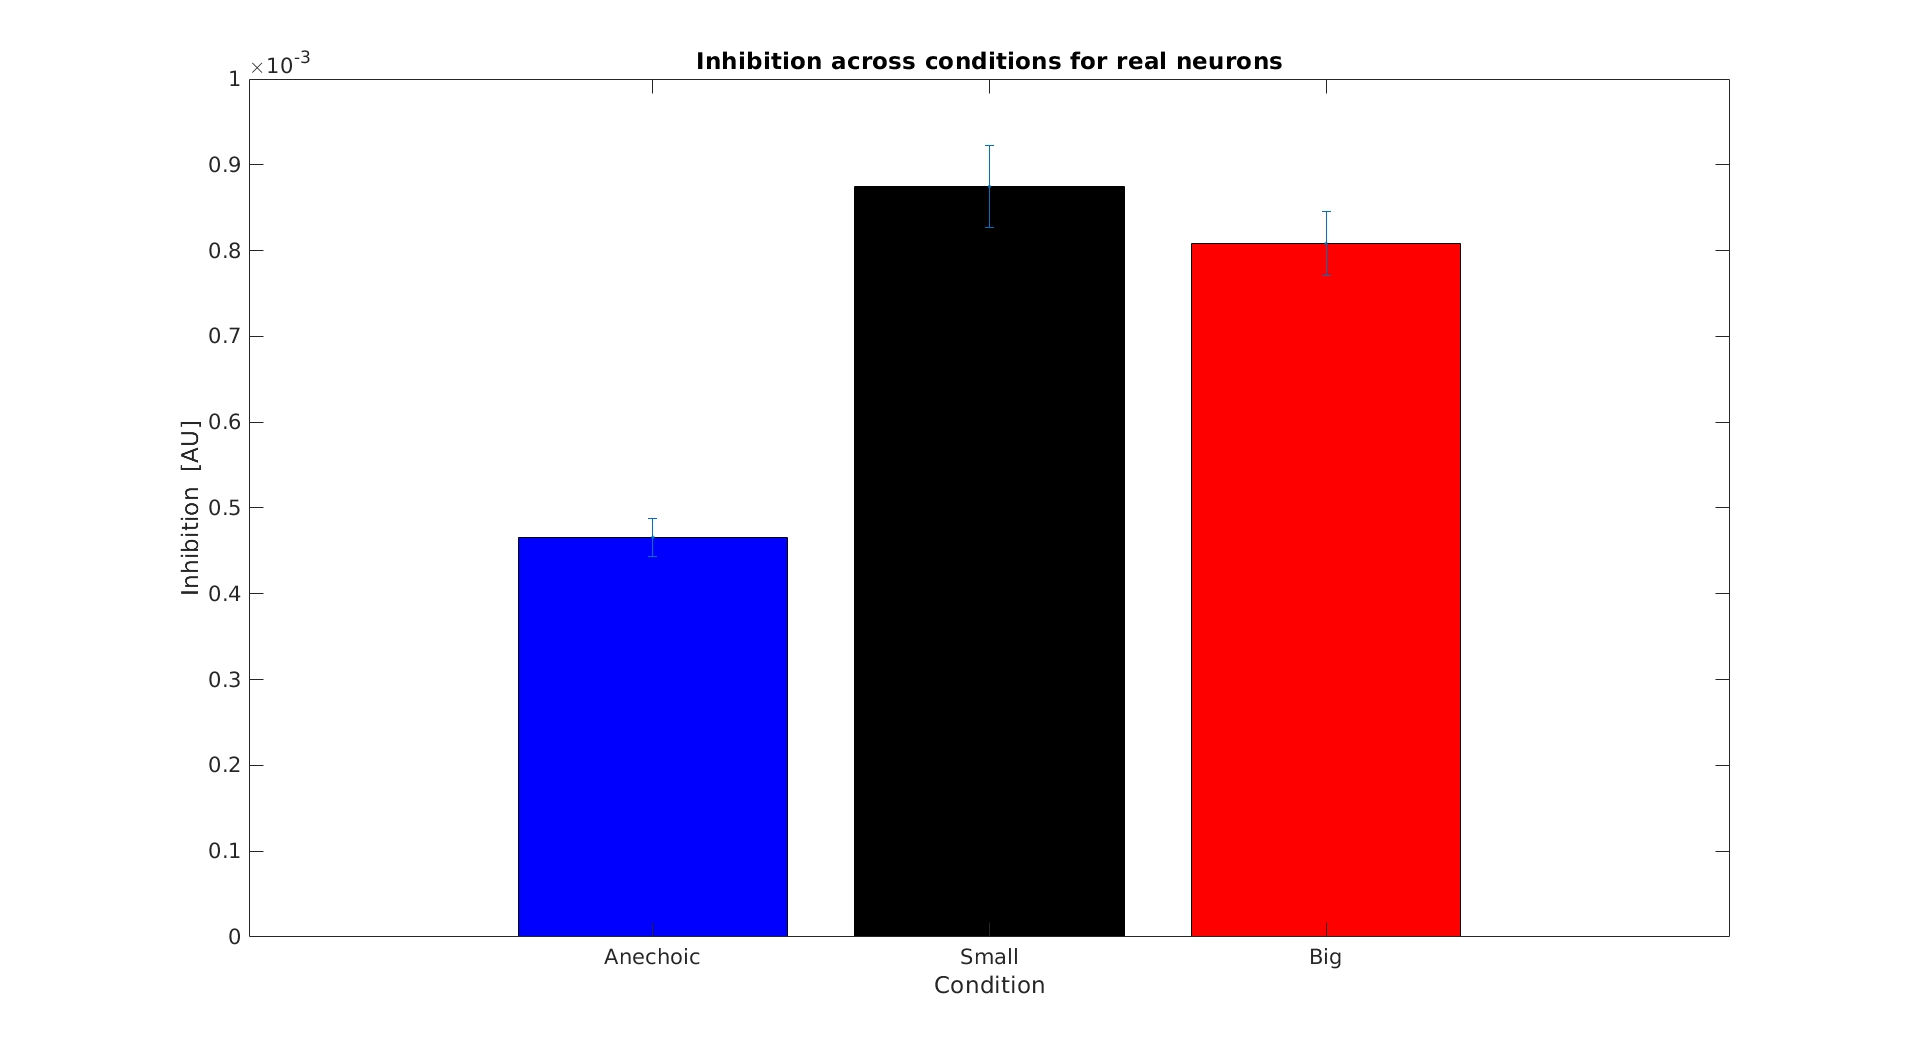

u_anech_i = mean(i_anech_all);
u_reverb1_i = mean(i_reverb1_all);
u_reverb2_i = mean(i_reverb2_all);
sz = length(i_anech_all);
sqrt_n = sqrt(sz);
sem_anech_i = std(i_anech_all)./sqrt_n;
sem_reverb1_i = std(i_reverb1_all)./sqrt_n;
sem_reverb2_i = std(i_reverb2_all)./sqrt_n;
figure('units','normalized','outerposition',[0 0 1 1]);
bar(1,u_anech_i,'b');hold on;
bar(2,u_reverb1_i,'k');
bar(3,u_reverb2_i,'r');
errorbar([1 2 3],[u_anech_i u_reverb1_i u_reverb2_i],[sem_anech_i sem_reverb1_i sem_reverb2_i],'.');
xticks([1:3]);
xticklabels({'Anechoic','Small','Big'});
xlabel('Condition');
ylabel('Inhibition  [AU]');
title(['Inhibition across conditions for ',type,' neurons']);
set(0,'defaultAxesFontSize',16);
save_name = [dir_name,type,'_neurons_all_data_Inhibition_across_conditions.png'];
export_fig(save_name);

Plot diff histogram

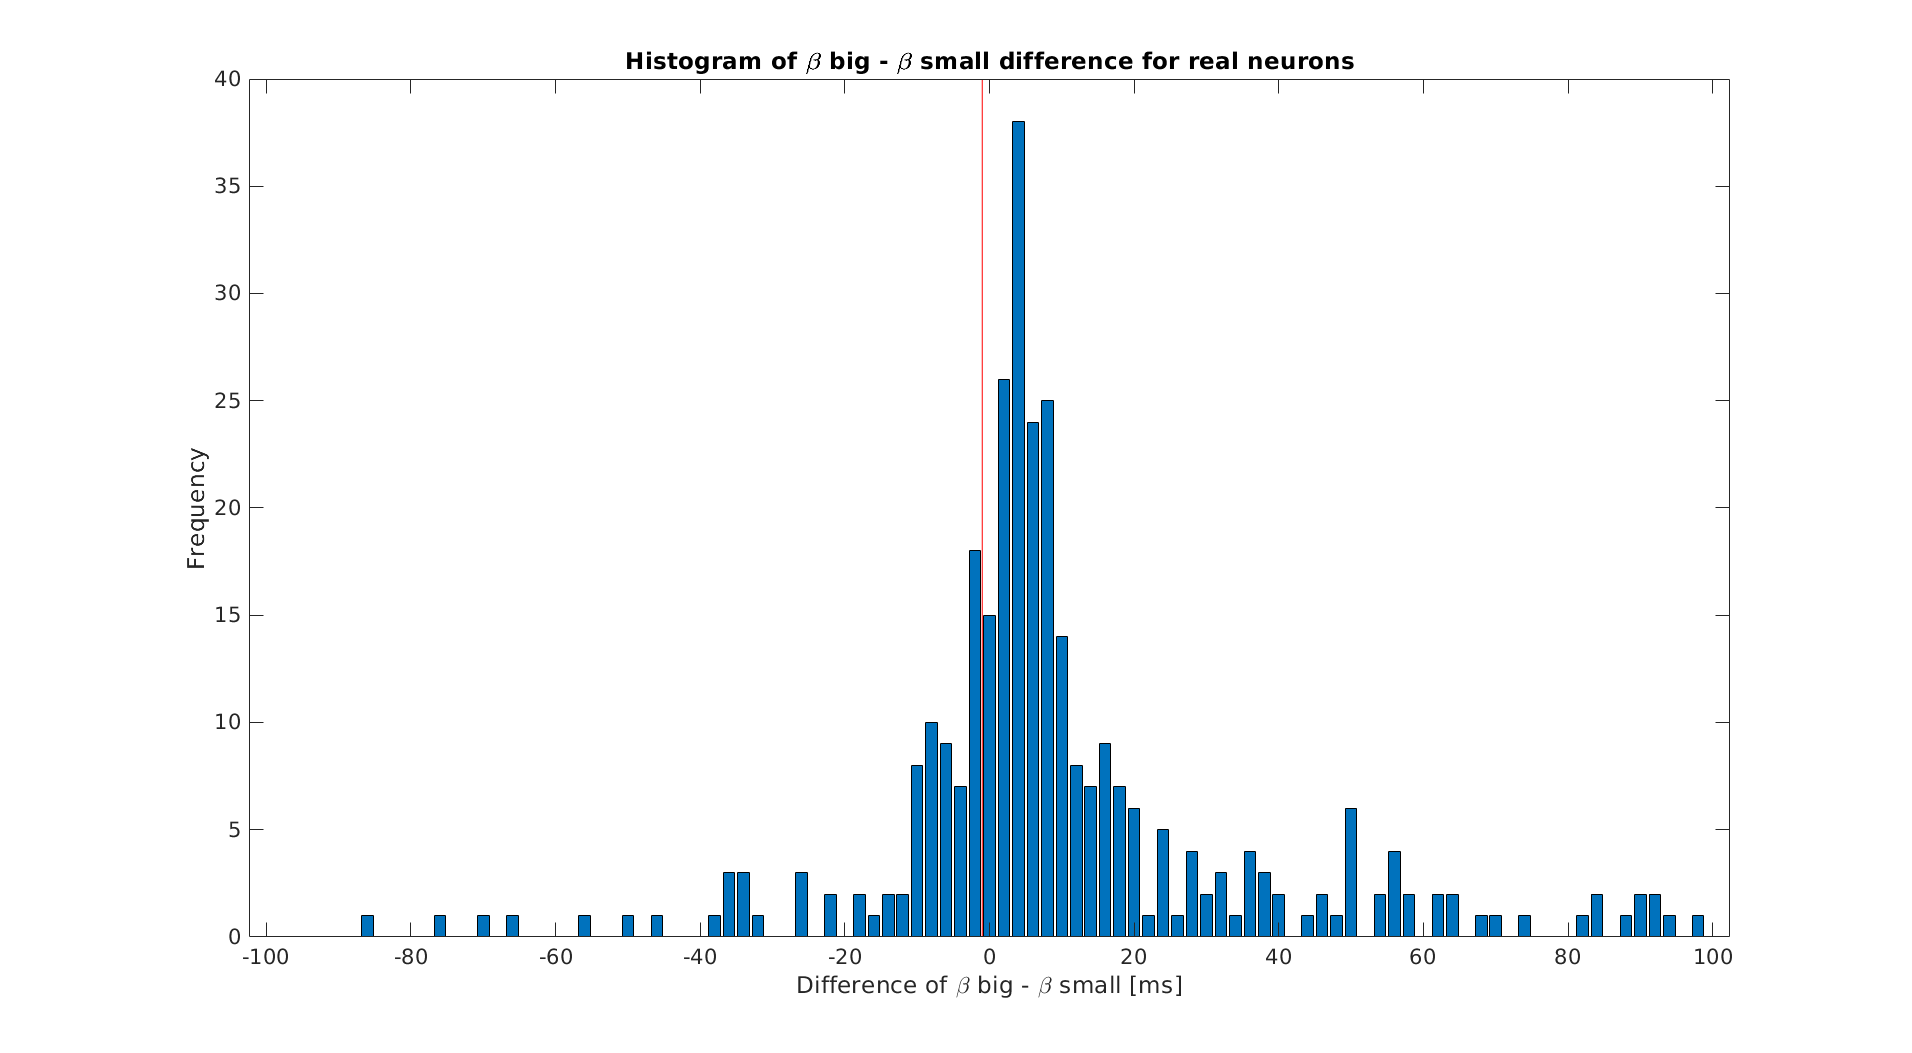

beta_diff = reach(params,'diff_big_small');
save([dir_name,type,'_diff'],'beta_diff');
bin_width_ms = 2;
spacing = 10;
edge_ms = 100;
edges = [-edge_ms:bin_width_ms:edge_ms];
hist_diff = histc(beta_diff,edges);
figure('units','normalized','outerposition',[0 0 1 1]);
bar(hist_diff);
for jj = 1:numel(edges)
    x_labels{jj} = num2str(edges(jj),'%.0f');
end
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
xlabel('Difference of \beta big - \beta small [ms]');
ylabel('Frequency','FontSize',16);
title(['Histogram of \beta big - \beta small difference for ',type,' neurons']);
set(0,'defaultAxesFontSize',16);
save_name = [dir_name,type,'_neurons_all_data_histogram_diff.png'];
export_fig(save_name);

Plot percentage diff histogram

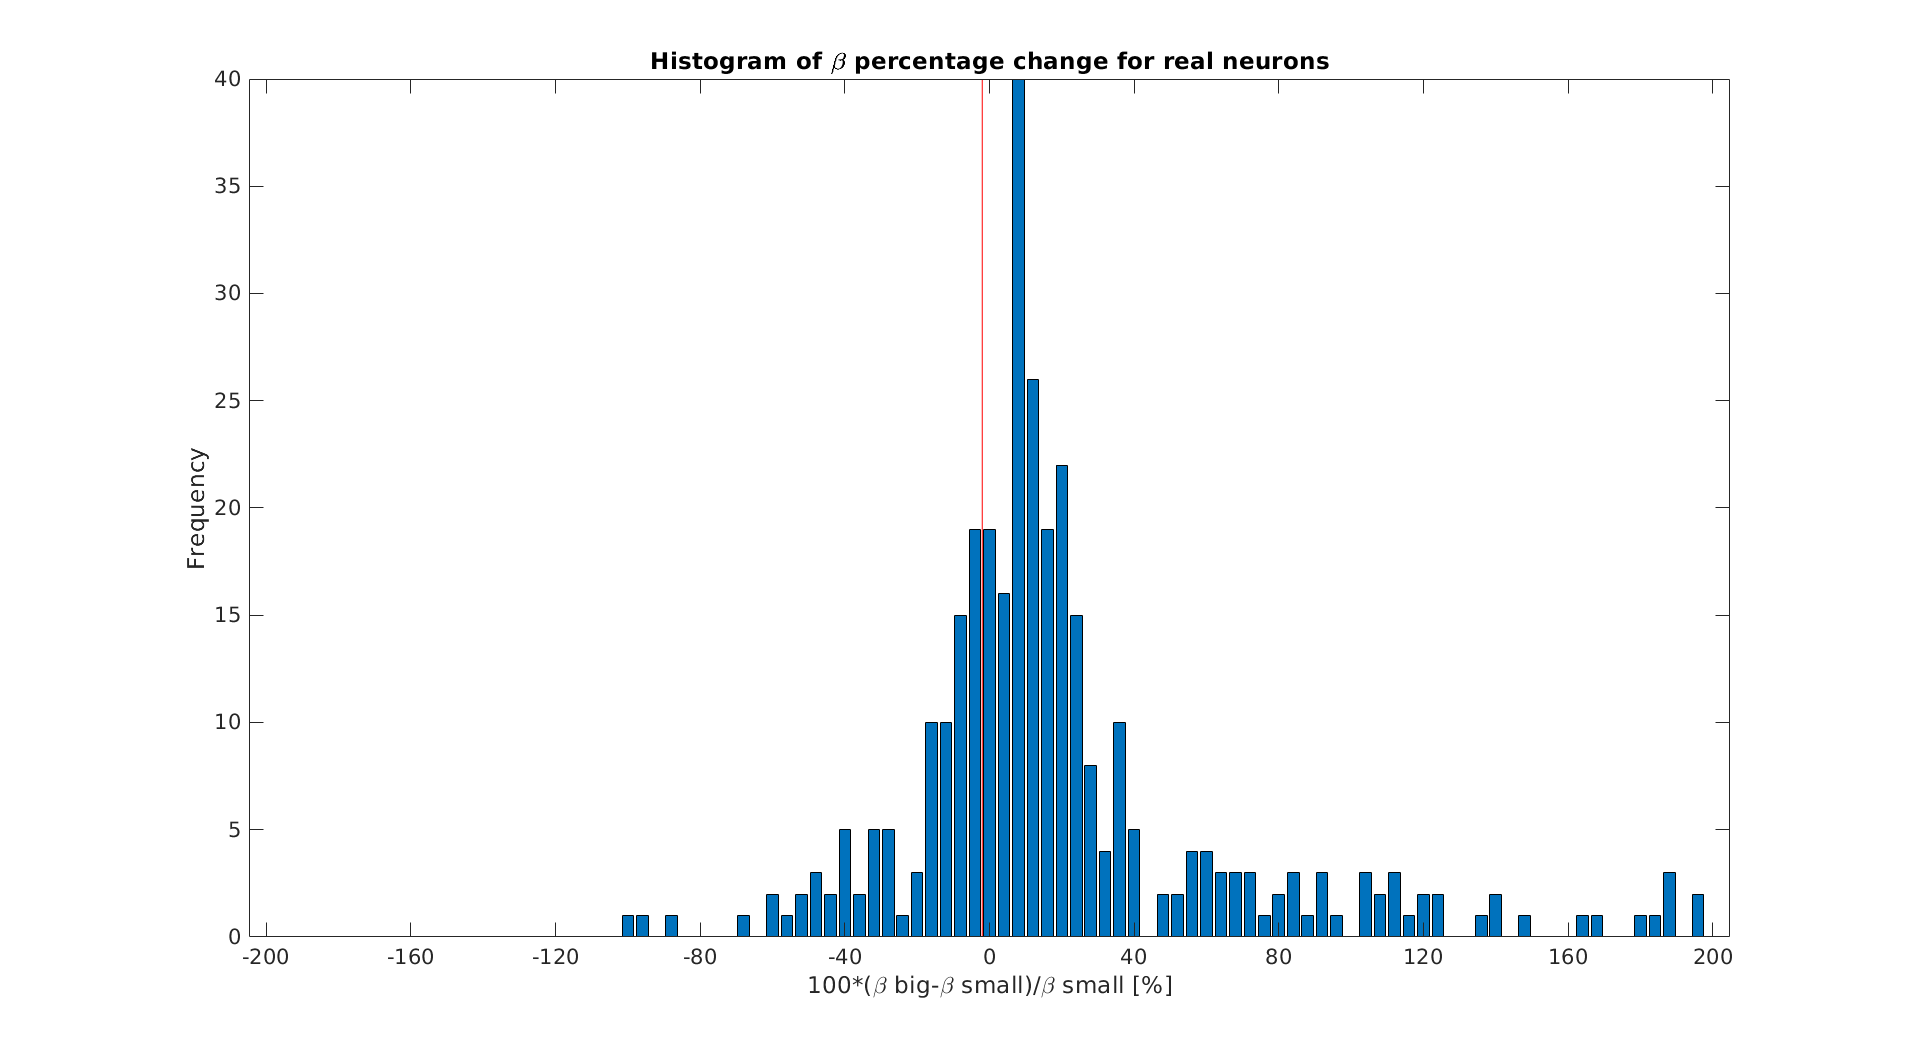

beta_per_diff = reach(params,'per_big_small');
bin_width_per = 4;
spacing = 10;
edge_per = 200;
edges = [-edge_per:bin_width_per:edge_per];
hist_diff_per = histc(beta_per_diff,edges);
figure('units','normalized','outerposition',[0 0 1 1]);
bar(hist_diff_per);
for jj = 1:numel(edges)
    x_labels{jj} = num2str(edges(jj),'%.0f');
end
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
xlabel('100*(\beta big-\beta small)/\beta small [%]');
ylabel('Frequency','FontSize',16);
title(['Histogram of \beta percentage change for ',type,' neurons']);
set(0,'defaultAxesFontSize',16);
save_name = [dir_name,type,'_neurons_all_data_histogram_diff_per.png'];
export_fig(save_name);

Plot (b_big - b_small)/(b_big+b_big) histogram

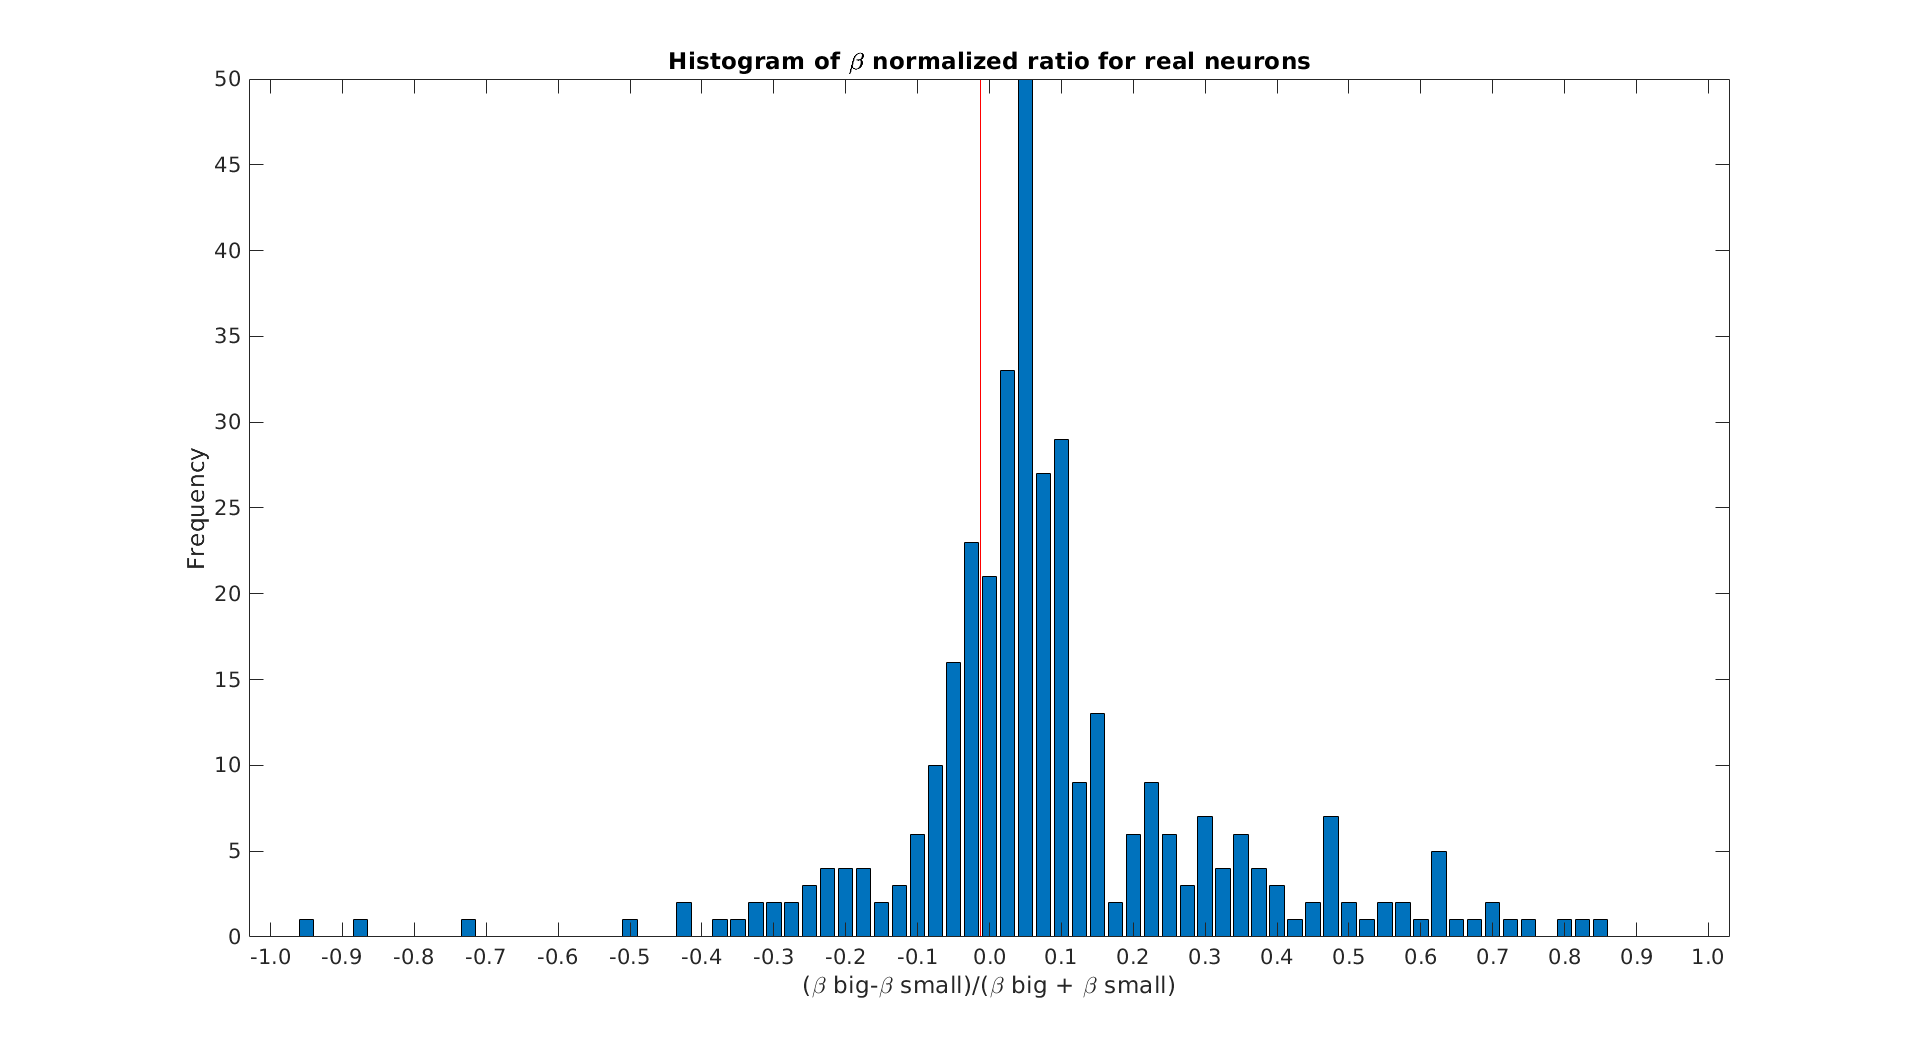

beta_norm_diff = reach(params,'ratio_adj_big_small');
bin_norm = 0.025;
spacing = 4;
edge_norm = 1;
edges = [-edge_norm:bin_norm:edge_norm];
hist_diff_norm = histc(beta_norm_diff,edges);
figure('units','normalized','outerposition',[0 0 1 1]);
bar(hist_diff_norm);
for jj = 1:numel(edges)
    x_labels{jj} = num2str(edges(jj),'%.1f');
end
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
xlabel('(\beta big-\beta small)/(\beta big + \beta small)');
ylabel('Frequency','FontSize',16);
title(['Histogram of \beta normalized ratio for ',type,' neurons']);
set(0,'defaultAxesFontSize',16);
save_name = [dir_name,type,'_neurons_all_data_histogram_ratio_norm.png'];
export_fig(save_name);

Plot (b_big - b_small)/(b_big+b_big) histogram

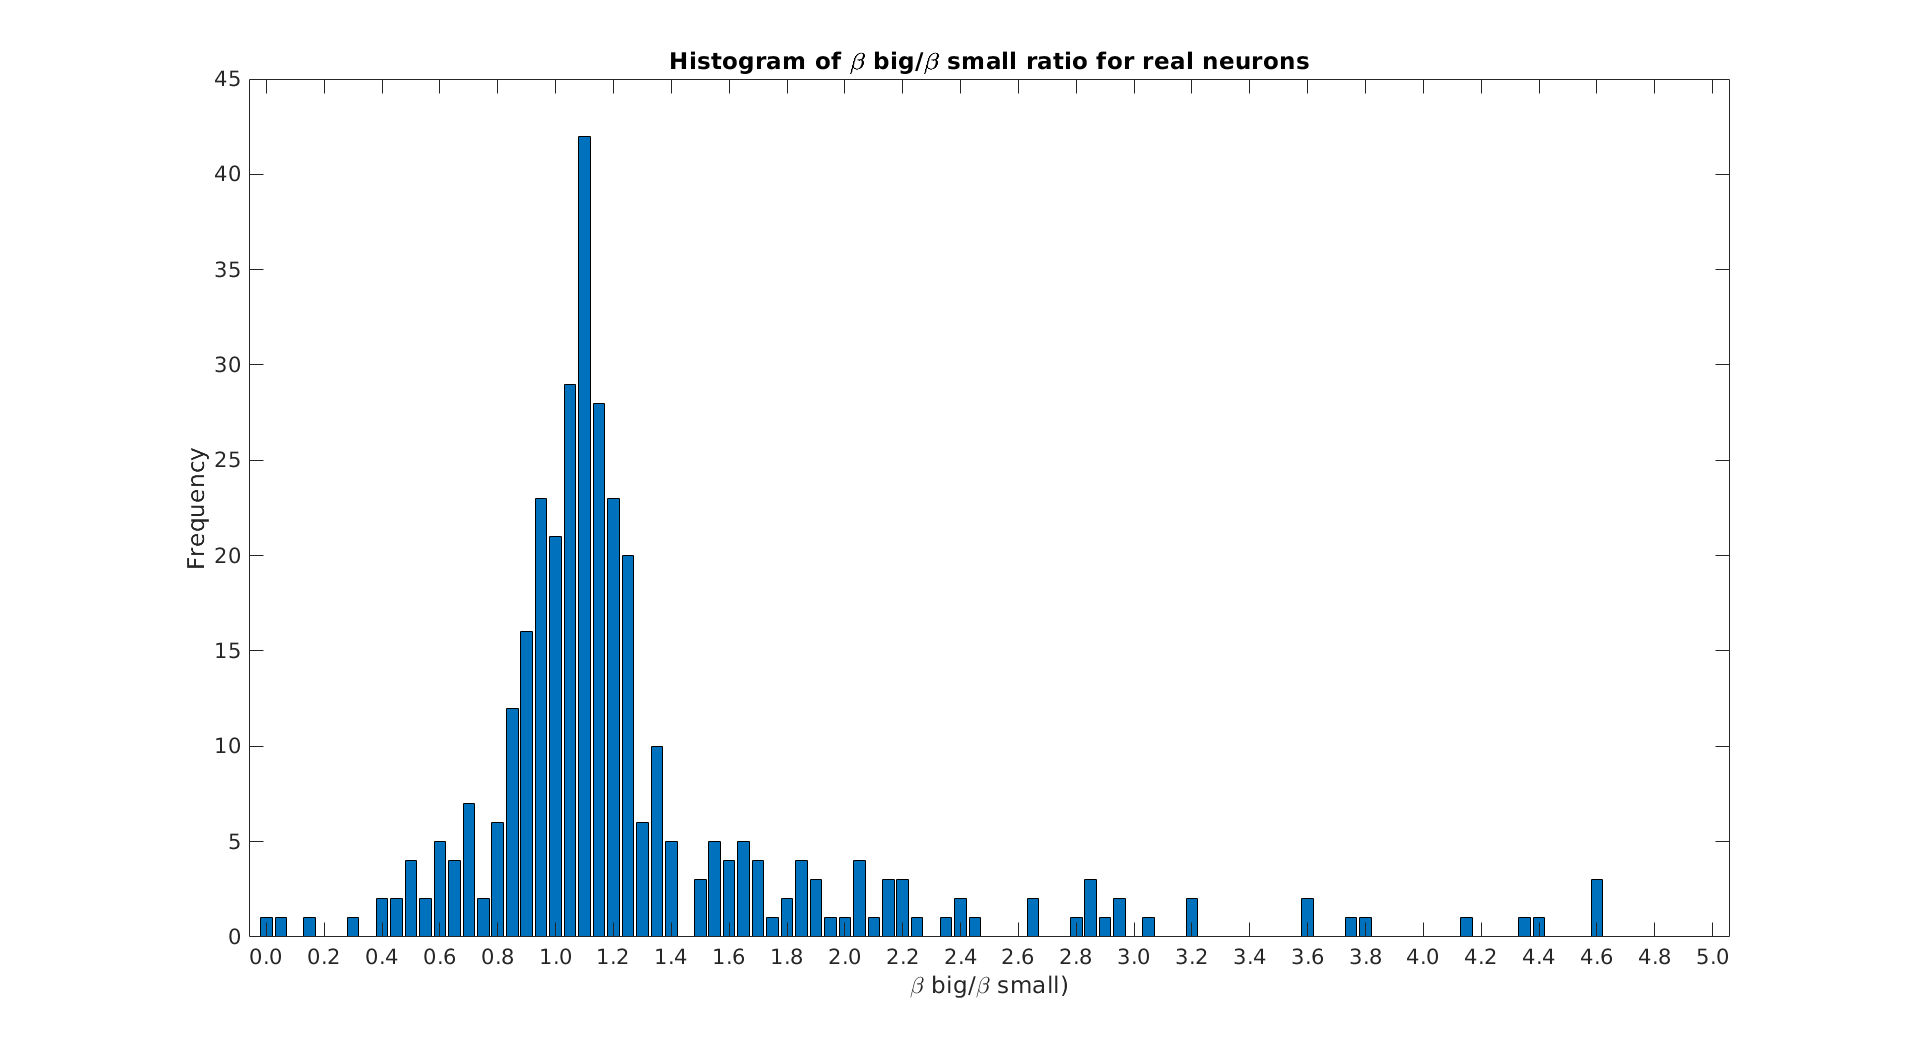

beta_ratio = reach(params,'ratio_big_small');
bin_ratio = 0.05;
spacing = 4;
edge_end = 5;
edges = [0:bin_ratio:edge_end];
hist_ratio = histc(beta_ratio,edges);
figure('units','normalized','outerposition',[0 0 1 1]);
bar(hist_ratio);
for jj = 1:numel(edges)
    x_labels{jj} = num2str(edges(jj),'%.1f');
end
% vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
xlabel('\beta big/\beta small)');
ylabel('Frequency','FontSize',16);
title(['Histogram of \beta big/\beta small ratio for ',type,' neurons']);
set(0,'defaultAxesFontSize',16);
save_name = [dir_name,type,'_neurons_all_data_histogram_ratio.png'];
export_fig(save_name);

Plot beta ratio vs NPSP

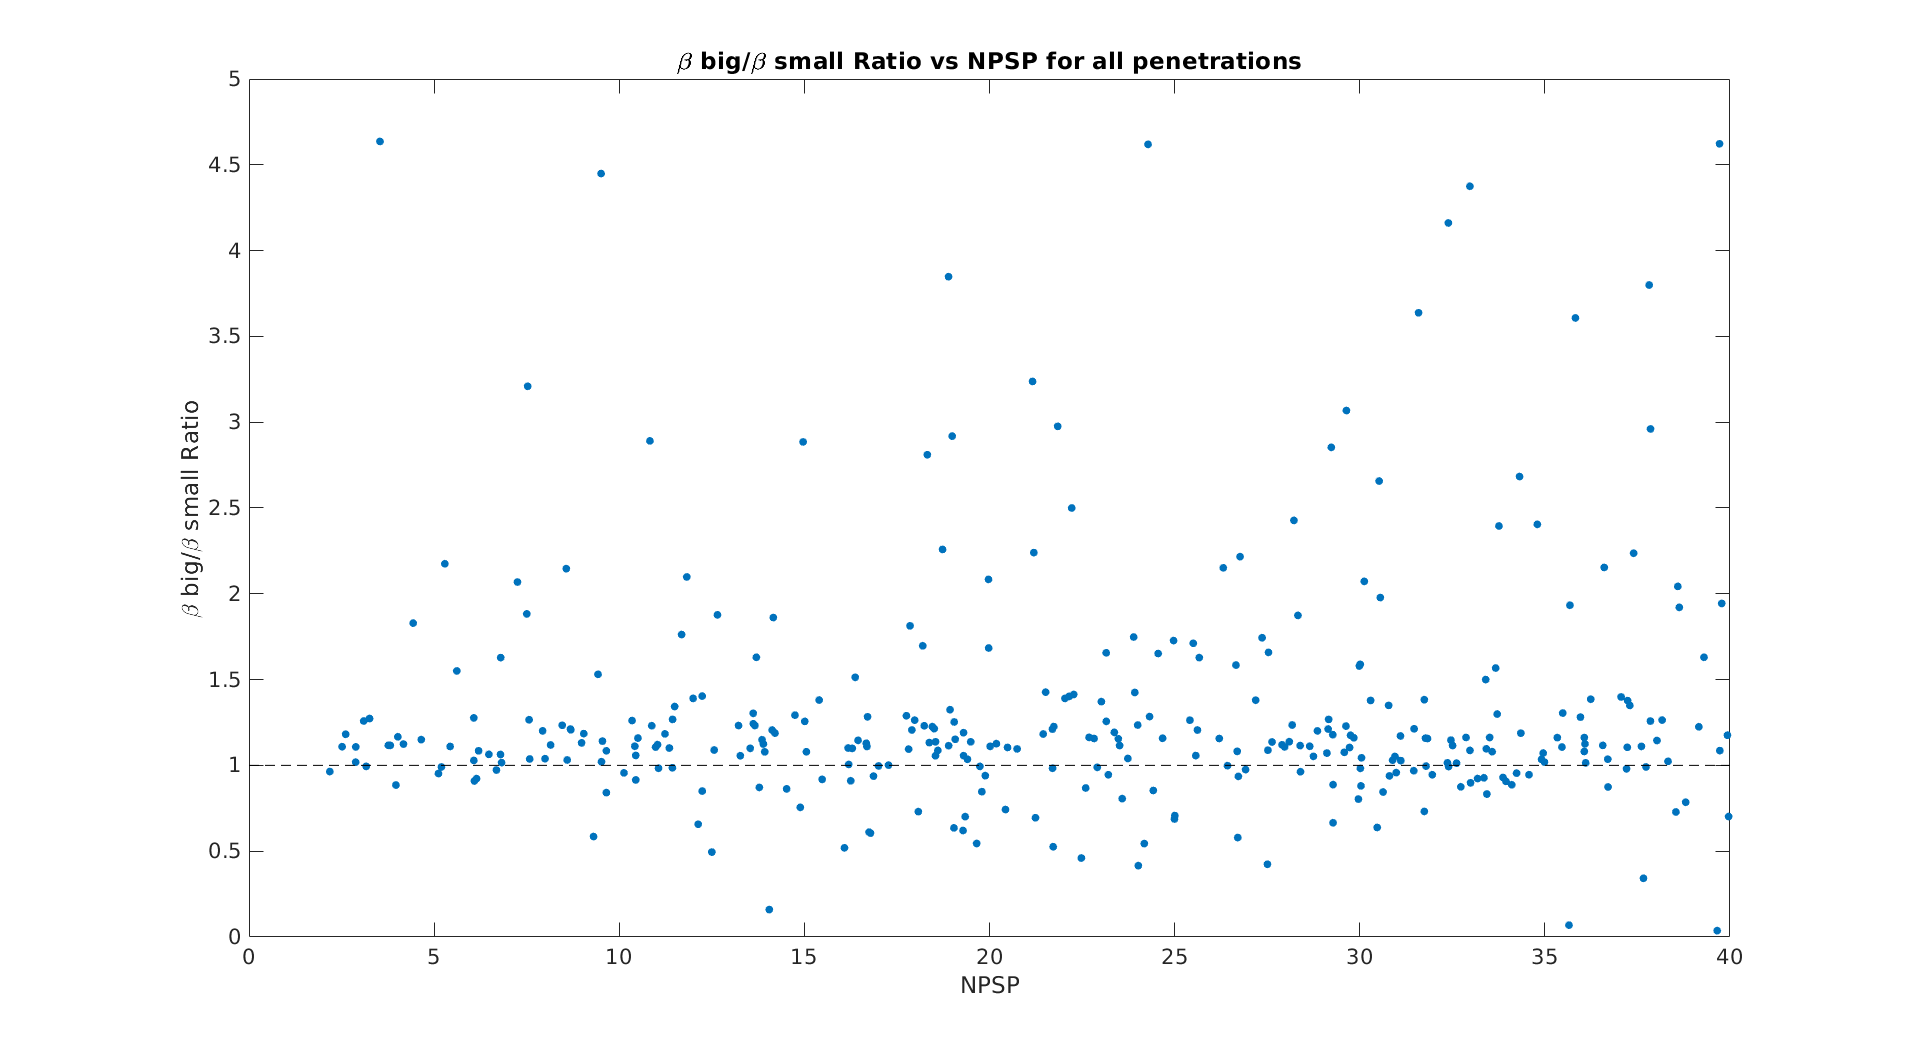

anech_beta = reach(params,'beta_anech');
big_beta = reach(params,'beta_big');
small_beta = reach(params,'beta_small');
NPSP = reach(params,'NPSP');
sz = 20;
NPSP_val = 40;
figure('units','normalized','outerposition',[0 0 1 1]);
plot(NPSP,beta_ratio,'.','MarkerSize',sz);hold on;
xlabel('NPSP');
ylabel('\beta big/\beta small Ratio');
title('\beta big/\beta small Ratio vs NPSP for all penetrations');
plot([0:40],ones(41,1),'k--');
ylim([0 5]);
save_name = [dir_name,type,'_neurons_all_data_beta_ratio_vs_NPSP.png'];
export_fig(save_name);

NPSP_small = NPSP(NPSP<NPSP_val);
s = signtest(big_beta,small_beta);
s_median = median(big_beta - small_beta);
s_mean = mean(big_beta - small_beta);
s_small = signtest(big_beta(NPSP<NPSP_val),small_beta(NPSP<NPSP_val)); 
s_median_small = median(big_beta(NPSP<NPSP_val) - small_beta(NPSP<NPSP_val));
s_mean_small = mean(big_beta(NPSP<NPSP_val) - small_beta(NPSP<NPSP_val));

Plot betas vs NPSP

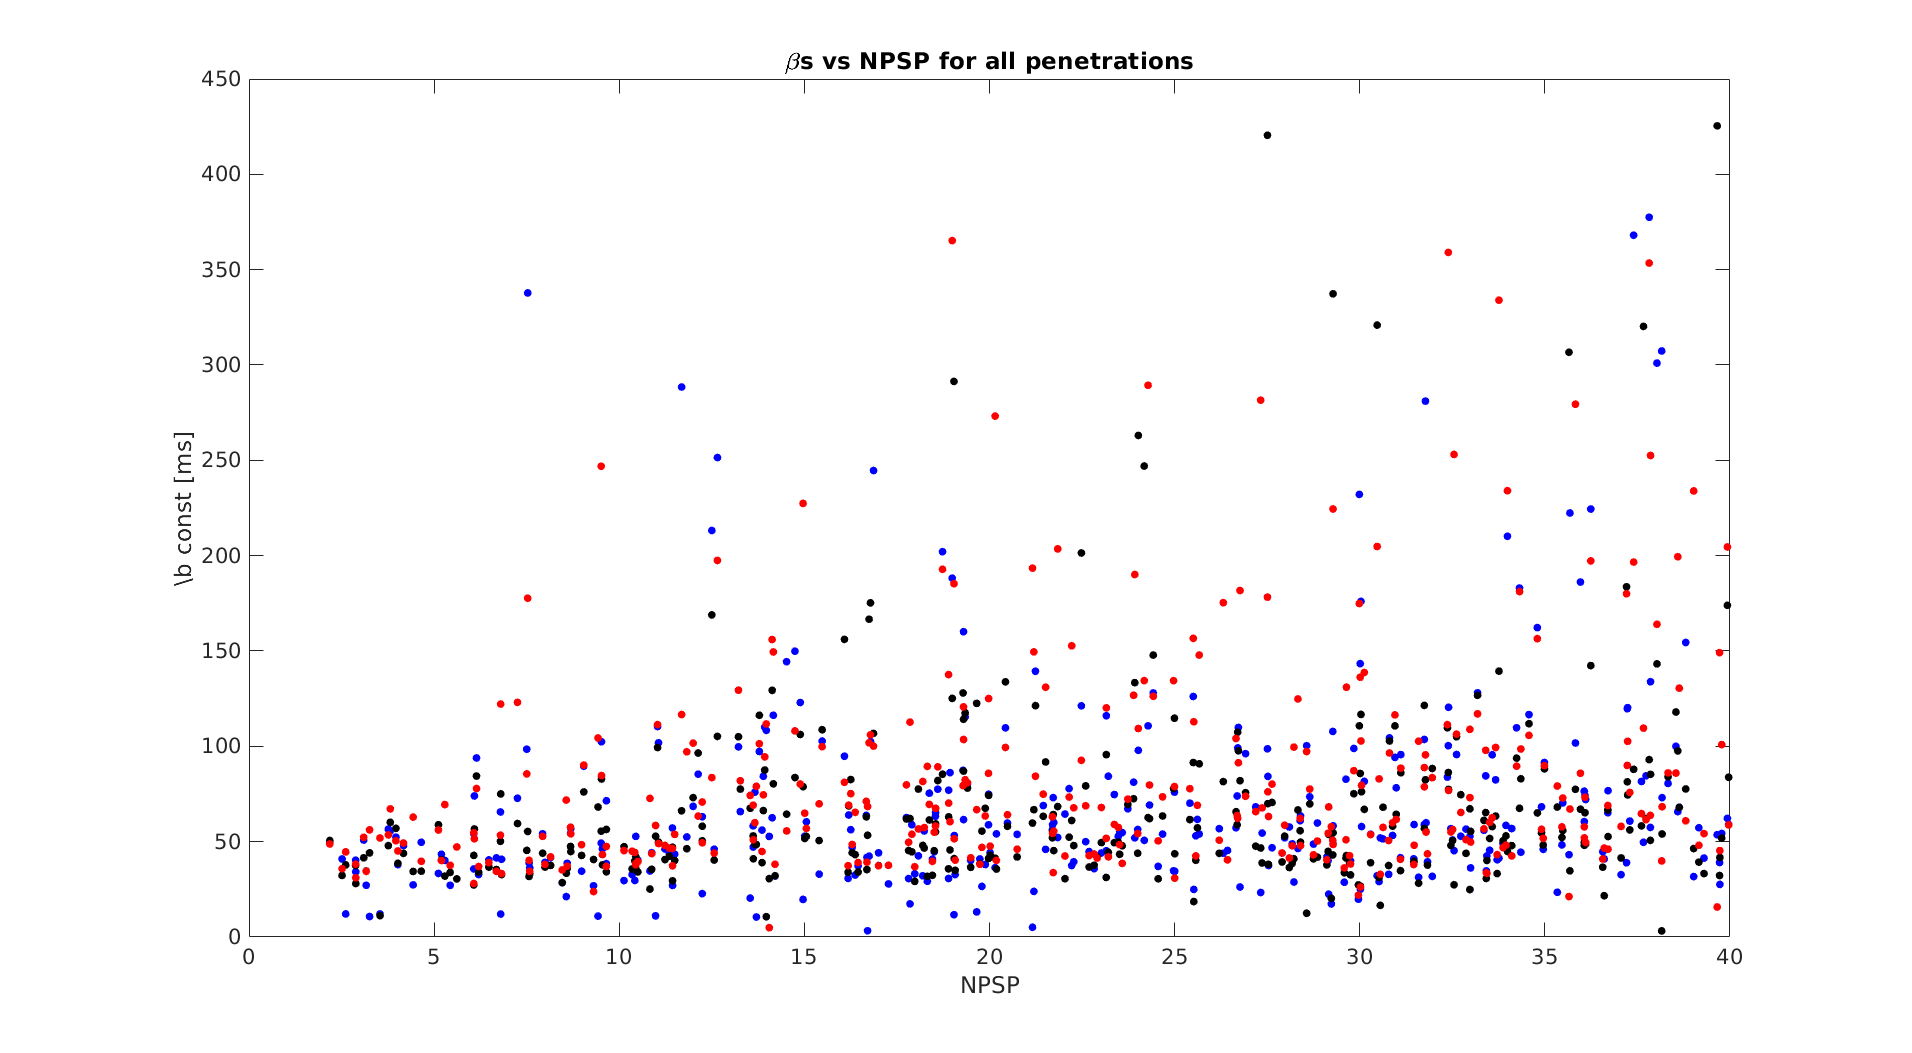

NPSP = reach(params,'NPSP');
sz = 20;
figure('units','normalized','outerposition',[0 0 1 1]);
plot(NPSP,anech_beta,'b.','MarkerSize',sz);hold on;
plot(NPSP,small_beta,'k.','MarkerSize',sz);
plot(NPSP,big_beta,'r.','MarkerSize',sz);
xlabel('NPSP');
ylabel('\b const [ms]');
title('\betas vs NPSP for all penetrations');
% plot([0:40],ones(41,1),'k--');
% ylim([0 5]);
save_name = [dir_name,type,'_neurons_all_data_betas_vs_NPSP.png'];
export_fig(save_name);

Plot Bs vs NPSP

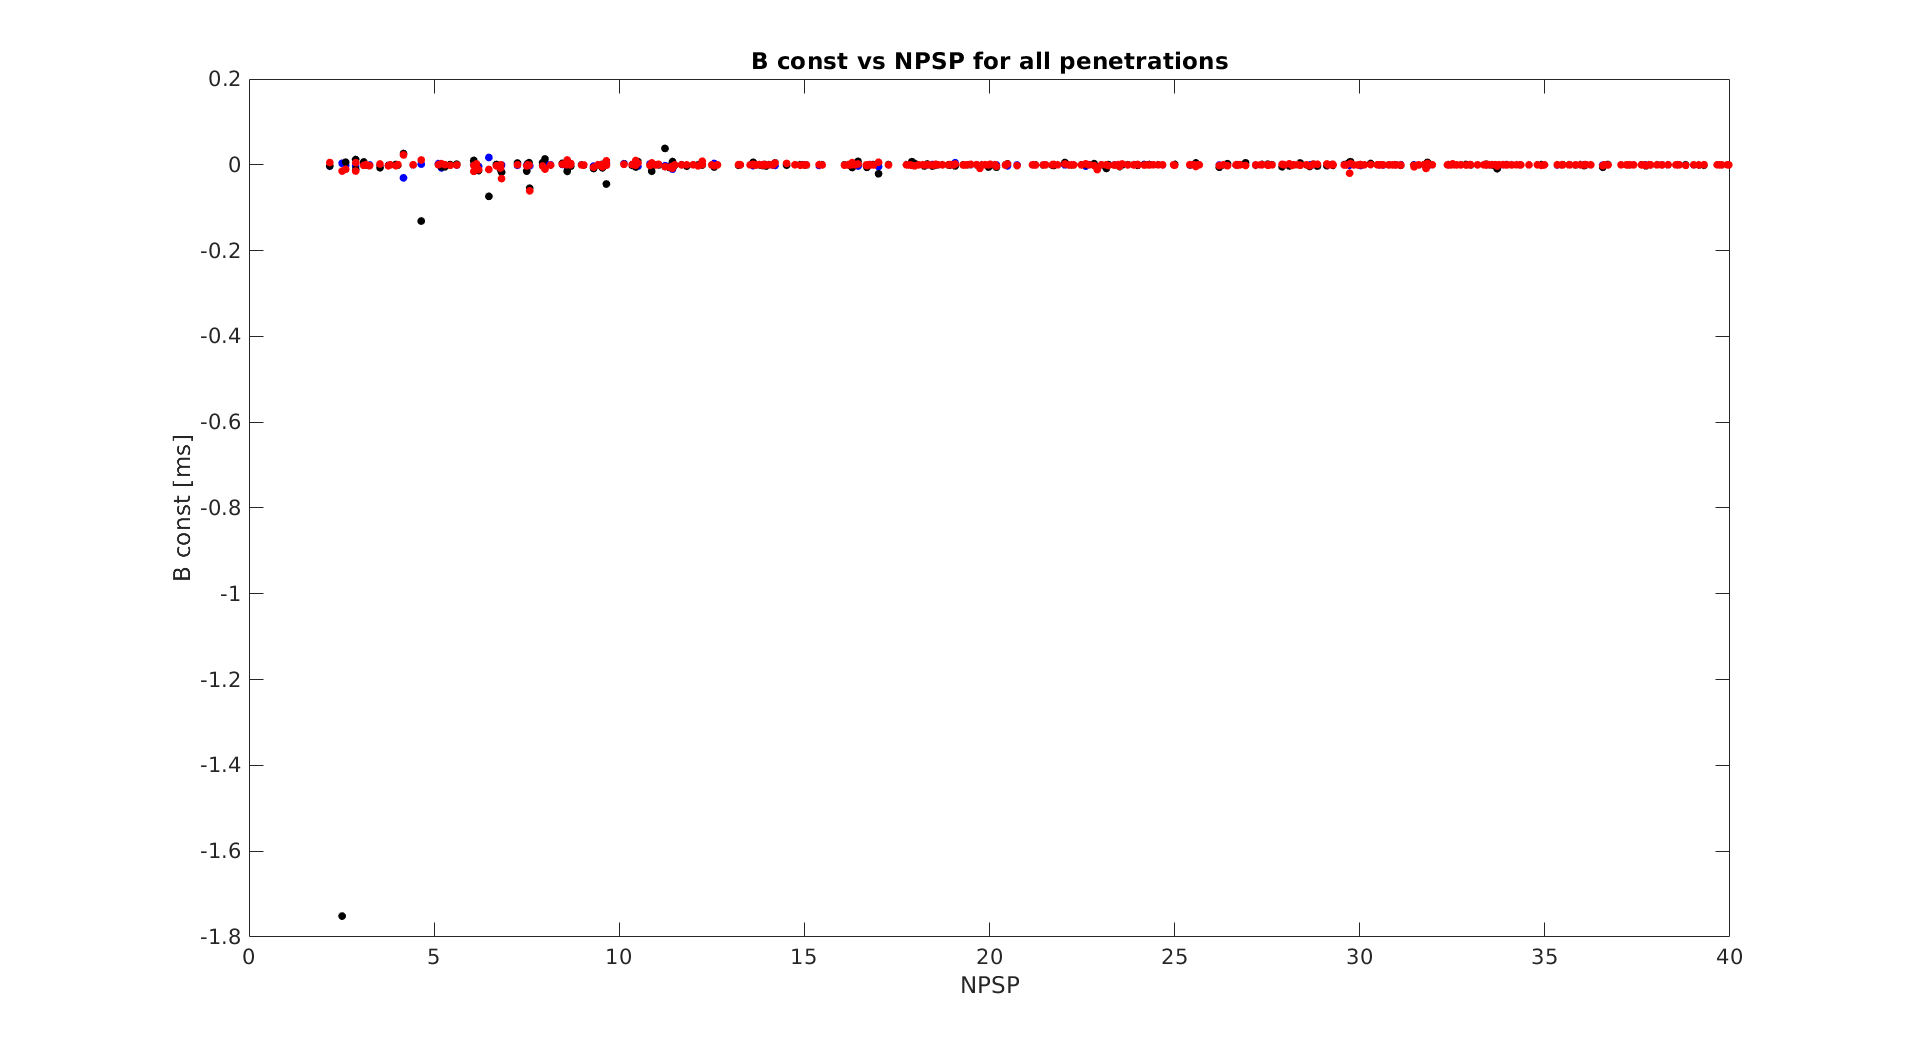

sz = 20;
figure('units','normalized','outerposition',[0 0 1 1]);
plot(NPSP,B_anech_all,'b.','MarkerSize',sz);hold on;
plot(NPSP,B_reverb1_all,'k.','MarkerSize',sz);
plot(NPSP,B_reverb2_all,'r.','MarkerSize',sz);
xlabel('NPSP');
ylabel('B const [ms]');
title('B const vs NPSP for all penetrations');
% plot([0:40],ones(41,1),'k--');
% ylim([0 5]);
save_name = [dir_name,type,'_neurons_all_data_Bs_vs_NPSP.png'];
export_fig(save_name);

Plot I/E ratio vs NPSP

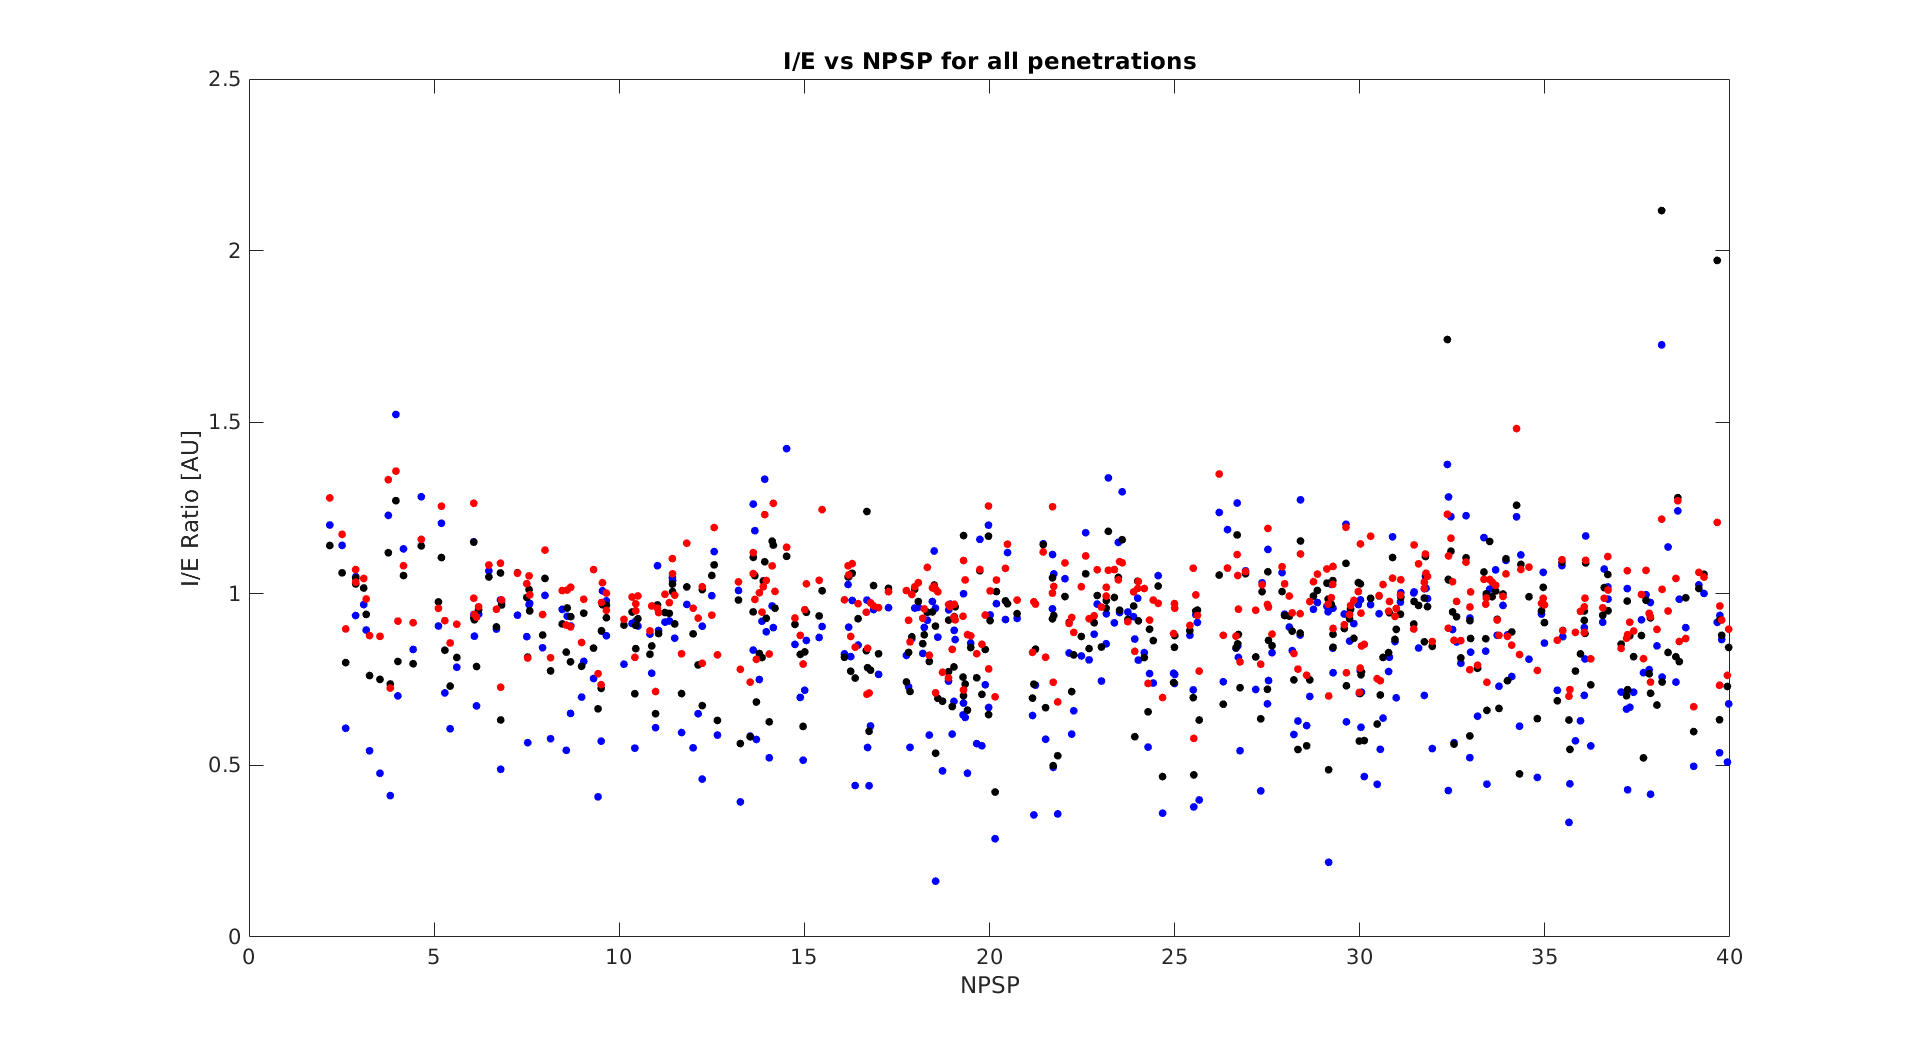

sz = 20;
figure('units','normalized','outerposition',[0 0 1 1]);
plot(NPSP,ie_anech_all,'b.','MarkerSize',sz);hold on;
plot(NPSP,ie_reverb1_all,'k.','MarkerSize',sz);
plot(NPSP,ie_reverb2_all,'r.','MarkerSize',sz);
xlabel('NPSP');
ylabel('I/E Ratio [AU]');
title('I/E vs NPSP for all penetrations');
% plot([0:40],ones(41,1),'k--');
% ylim([0 5]);
save_name = [dir_name,type,'_neurons_all_data_IEratio_vs_NPSP.png'];
export_fig(save_name);

Plot  Inhibition vs NPSP

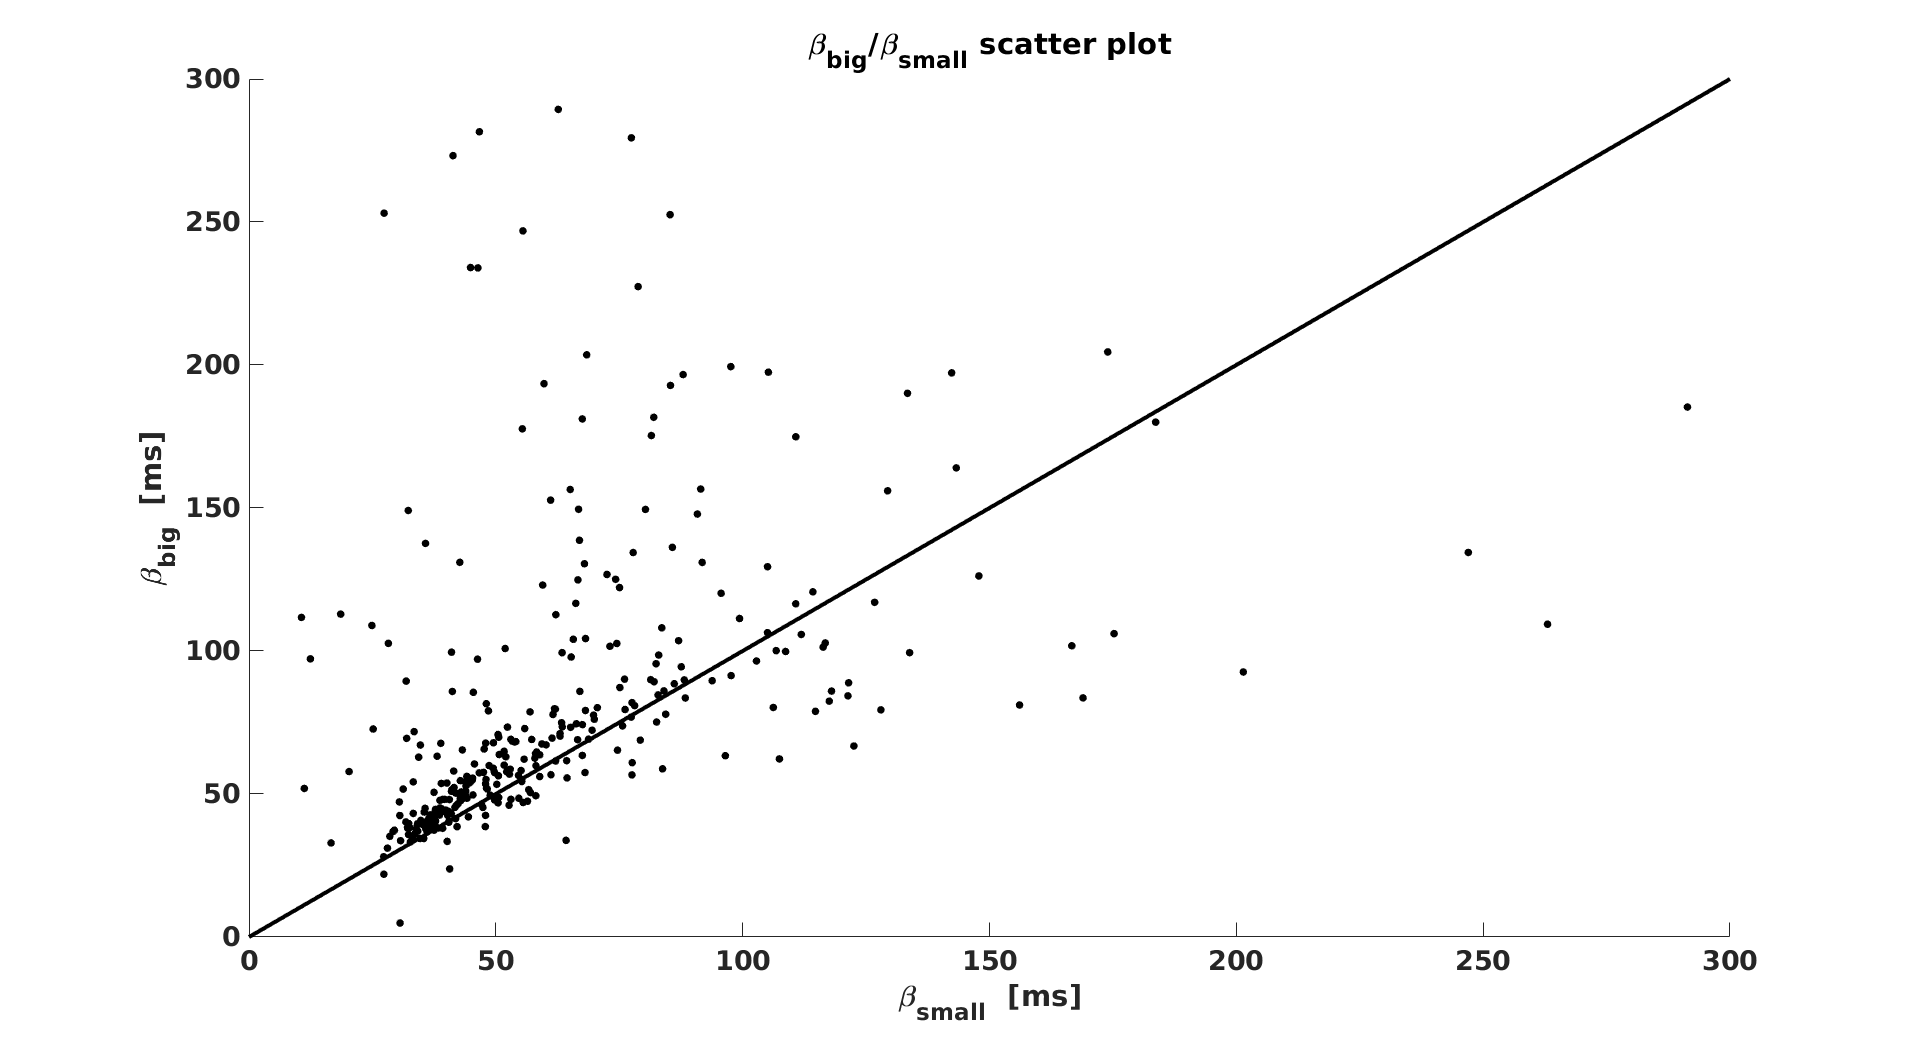

sz = 20;
figure('units','normalized','outerposition',[0 0 1 1]);
plot(NPSP,i_anech_all,'b.','MarkerSize',sz);hold on;
plot(NPSP,i_reverb1_all,'k.','MarkerSize',sz);
plot(NPSP,i_reverb2_all,'r.','MarkerSize',sz);
hold off;
xlabel('NPSP');
ylabel('Inhibition [AU]');
title('Inhibition vs NPSP for all penetrations');
% plot([0:40],ones(41,1),'k--');
% ylim([0 5]);
save_name = [dir_name,type,'_neurons_all_data_Inhibition_vs_NPSP.png'];
export_fig(save_name);

close;

Get all Quality Summary Variables

CC_dexp(1,:) = reach(params,'CC_dexp_anech');
CC_dexp(2,:) = reach(params,'CC_dexp_reverb1');
CC_dexp(3,:) = reach(params,'CC_dexp_reverb2');
CC_dexp_mean = mean(CC_dexp);
RMSE_dexp(1,:) = reach(params,'RMSE_dexp_anech');
RMSE_dexp(2,:) = reach(params,'RMSE_dexp_reverb1');
RMSE_dexp(3,:) = reach(params,'RMSE_dexp_reverb2');
RMSE_dexp_mean = mean(RMSE_dexp);
CC_data(1,:) = reach(params,'CC_anech');
CC_data(2,:) = reach(params,'CC_reverb1');
CC_data(3,:) = reach(params,'CC_reverb2');
CC_data_mean = mean(CC_data);
RMSE_data(1,:) = reach(params,'RMSE_anech');
RMSE_data(2,:) = reach(params,'RMSE_reverb1');
RMSE_data(3,:) = reach(params,'RMSE_reverb2');
RMSE_data_mean = mean(RMSE_data);

Plot betas vs CC_dexp; RMSE_dexp; CC_data; RMSE_data

if plot_controls
    sz = 20;
    CC_dexp_mean = mean(CC_dexp);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(CC_dexp_mean,anech_beta,'b.','MarkerSize',sz);hold on;
    plot(CC_dexp_mean,small_beta,'k.','MarkerSize',sz);
    plot(CC_dexp_mean,big_beta,'r.','MarkerSize',sz);
    xlabel('\mu(CC dexp)');
    ylabel('\beta [ms]');
    title('\beta  vs \mu(CC dexp) for all penetrations');
    
    RMSE_dexp_mean = mean(RMSE_dexp);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(RMSE_dexp_mean,anech_beta,'b.','MarkerSize',sz);hold on;
    plot(RMSE_dexp_mean,small_beta,'k.','MarkerSize',sz);
    plot(RMSE_dexp_mean,big_beta,'r.','MarkerSize',sz);
    xlabel('\mu(RMSE dexp)');
    ylabel('\beta [ms]');
    title('\beta  vs \mu(RMSE dexp) for all penetrations');
    
    CC_data_mean = mean(CC_data);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(CC_data_mean,anech_beta,'b.','MarkerSize',sz);hold on;
    plot(CC_data_mean,small_beta,'k.','MarkerSize',sz);
    plot(CC_data_mean,big_beta,'r.','MarkerSize',sz);
    xlabel('\mu(CC data)');
    ylabel('\beta [ms]');
    title('\beta  vs \mu(CC data) for all penetrations');
    
    RMSE_data_mean = mean(RMSE_data);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(RMSE_data_mean,anech_beta,'b.','MarkerSize',sz);hold on;
    plot(RMSE_data_mean,small_beta,'k.','MarkerSize',sz);
    plot(RMSE_data_mean,big_beta,'r.','MarkerSize',sz);
    xlabel('\mu(RMSE data)');
    ylabel('\beta [ms]');
    title('\beta  vs \mu(RMSE data) for all penetrations');
end

Plot I/E ratio vs CC_dexp; RMSE_dexp; CC_data; RMSE_data

if plot_controls
    sz = 20;
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(CC_dexp_mean,ie_anech_all,'b.','MarkerSize',sz);hold on;
    plot(CC_dexp_mean,ie_reverb1_all,'k.','MarkerSize',sz);
    plot(CC_dexp_mean,ie_reverb2_all,'r.','MarkerSize',sz);
    xlabel('\mu(CC dexp)');
    ylabel('I/E ratio [AU]');
    title('I/E ratio  vs \mu(CC dexp) for all penetrations');
    
    
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(RMSE_dexp_mean,ie_anech_all,'b.','MarkerSize',sz);hold on;
    plot(RMSE_dexp_mean,ie_reverb1_all,'k.','MarkerSize',sz);
    plot(RMSE_dexp_mean,ie_reverb2_all,'r.','MarkerSize',sz);
    xlabel('\mu(RMSE dexp)');
    ylabel('I/E ratio [AU]');
    title('I/E ratio  vs \mu(RMSE dexp) for all penetrations');
    
    CC_data_mean = mean(CC_data);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(CC_data_mean,ie_anech_all,'b.','MarkerSize',sz);hold on;
    plot(CC_data_mean,ie_reverb1_all,'k.','MarkerSize',sz);
    plot(CC_data_mean,ie_reverb2_all,'r.','MarkerSize',sz);
    xlabel('\mu(CC data)');
    ylabel('I/E ratio [AU]');
    title('I/E ratio  vs \mu(CC data) for all penetrations');
    
    RMSE_data_mean = mean(RMSE_data);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(RMSE_data_mean,ie_anech_all,'b.','MarkerSize',sz);hold on;
    plot(RMSE_data_mean,ie_reverb1_all,'k.','MarkerSize',sz);
    plot(RMSE_data_mean,ie_reverb2_all,'r.','MarkerSize',sz);
    xlabel('Mean RMSE data');
    ylabel('I/E ratio [AU]');
    title('I/E ratio  vs \mu(RMSE data) for all penetrations');
end

Plot Inhibition  vs CC_dexp; RMSE_dexp; CC_data; RMSE_data

if plot_controls
    sz = 20;
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(CC_dexp_mean,i_anech_all,'b.','MarkerSize',sz);hold on;
    plot(CC_dexp_mean,i_reverb1_all,'k.','MarkerSize',sz);
    plot(CC_dexp_mean,i_reverb2_all,'r.','MarkerSize',sz);
    xlabel('\mu(CC dexp)');
    ylabel('Inhibition [AU]');
    title('Inhibition vs \mu(CC dexp) for all penetrations');
    
    
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(RMSE_dexp_mean,i_anech_all,'b.','MarkerSize',sz);hold on;
    plot(RMSE_dexp_mean,i_reverb1_all,'k.','MarkerSize',sz);
    plot(RMSE_dexp_mean,i_reverb2_all,'r.','MarkerSize',sz);
    xlabel('\mu(RMSE dexp)');
    ylabel('Inhibition [AU]');
    title('Inhibition vs \mu(RMSE dexp) for all penetrations');
    
    CC_data_mean = mean(CC_data);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(CC_data_mean,i_anech_all,'b.','MarkerSize',sz);hold on;
    plot(CC_data_mean,i_reverb1_all,'k.','MarkerSize',sz);
    plot(CC_data_mean,i_reverb2_all,'r.','MarkerSize',sz);
    xlabel('\mu(CC data)');
    ylabel('Inhibition [AU]');
    title('Inhibition vs \mu(CC data) for all penetrations');
    
    RMSE_data_mean = mean(RMSE_data);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(RMSE_data_mean,i_anech_all,'b.','MarkerSize',sz);hold on;
    plot(RMSE_data_mean,i_reverb1_all,'k.','MarkerSize',sz);
    plot(RMSE_data_mean,i_reverb2_all,'r.','MarkerSize',sz);
    xlabel('Mean RMSE data');
    ylabel('Inhibition [AU]');
    title('Inhibition vs \mu(RMSE data) for all penetrations');
end

Plot B  vs CC_dexp; RMSE_dexp; CC_data; RMSE_data

if plot_controls
    sz = 20;
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(CC_dexp_mean,B_anech_all,'b.','MarkerSize',sz);hold on;
    plot(CC_dexp_mean,B_reverb1_all,'k.','MarkerSize',sz);
    plot(CC_dexp_mean,B_reverb2_all,'r.','MarkerSize',sz);
    xlabel('\mu(CC dexp)');
    ylabel('B const [AU]');
    title('B const vs \mu(CC dexp) for all penetrations');
    
    
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(RMSE_dexp_mean,B_anech_all,'b.','MarkerSize',sz);hold on;
    plot(RMSE_dexp_mean,B_reverb1_all,'k.','MarkerSize',sz);
    plot(RMSE_dexp_mean,B_reverb2_all,'r.','MarkerSize',sz);
    xlabel('\mu(RMSE dexp)');
    ylabel('B const [AU]');
    title('B const vs \mu(RMSE dexp) for all penetrations');
    
    CC_data_mean = mean(CC_data);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(CC_data_mean,B_anech_all,'b.','MarkerSize',sz);hold on;
    plot(CC_data_mean,B_reverb1_all,'k.','MarkerSize',sz);
    plot(CC_data_mean,B_reverb2_all,'r.','MarkerSize',sz);
    xlabel('\mu(CC data)');
    ylabel('B const [AU]');
    title('B const vs \mu(CC data) for all penetrations');
    
    RMSE_data_mean = mean(RMSE_data);
    figure('units','normalized','outerposition',[0 0 1 1]);
    plot(RMSE_data_mean,B_anech_all,'b.','MarkerSize',sz);hold on;
    plot(RMSE_data_mean,B_reverb1_all,'k.','MarkerSize',sz);
    plot(RMSE_data_mean,B_reverb2_all,'r.','MarkerSize',sz);
    xlabel('Mean RMSE data');
    ylabel('B const [AU]');
    title('B const vs \mu(RMSE data) for all penetrations');
end

Plot the data according to the mu(RMSE dexp)

% ix_good_data = find(RMSE_dexp_mean<(0.5*(10^-4)));
ix_good_data = find(CC_dexp_mean>0.5);


Plot the scatter plot

figure('units','normalized','outerposition',[0 0 1 1]);
font_sz = 20;
font_label = 35;
sz = 25;
small_beta_plot = small_beta(ix_good_data);
big_beta_plot = big_beta(ix_good_data);
scatter(small_beta_plot,big_beta_plot,sz,'MarkerEdgeColor','k','MarkerFaceColor','k');
set(gca,'FontName','Arial','FontSize',font_sz,'FontWeight','Bold');
title('\beta_{big}/\beta_{small} scatter plot','FontSize',font_label,'FontWeight','bold');
xlabel('\beta_{small}  [ms]','FontSize',font_label,'FontWeight','bold');
ylabel('\beta_{big}  [ms]','FontSize',font_label,'FontWeight','bold');
lim_val = 300;
l = [0 lim_val];
xlim(l);
ylim(l);
hline = refline(1,0);
hline.Color = 'k';
hline.LineWidth = 3;
set(gcf,'color','w');
file_name = [sfn_dir,'Scatter_plot.jpg'];
export_fig(file_name);

Plot percentage diff histogram (big vs small)

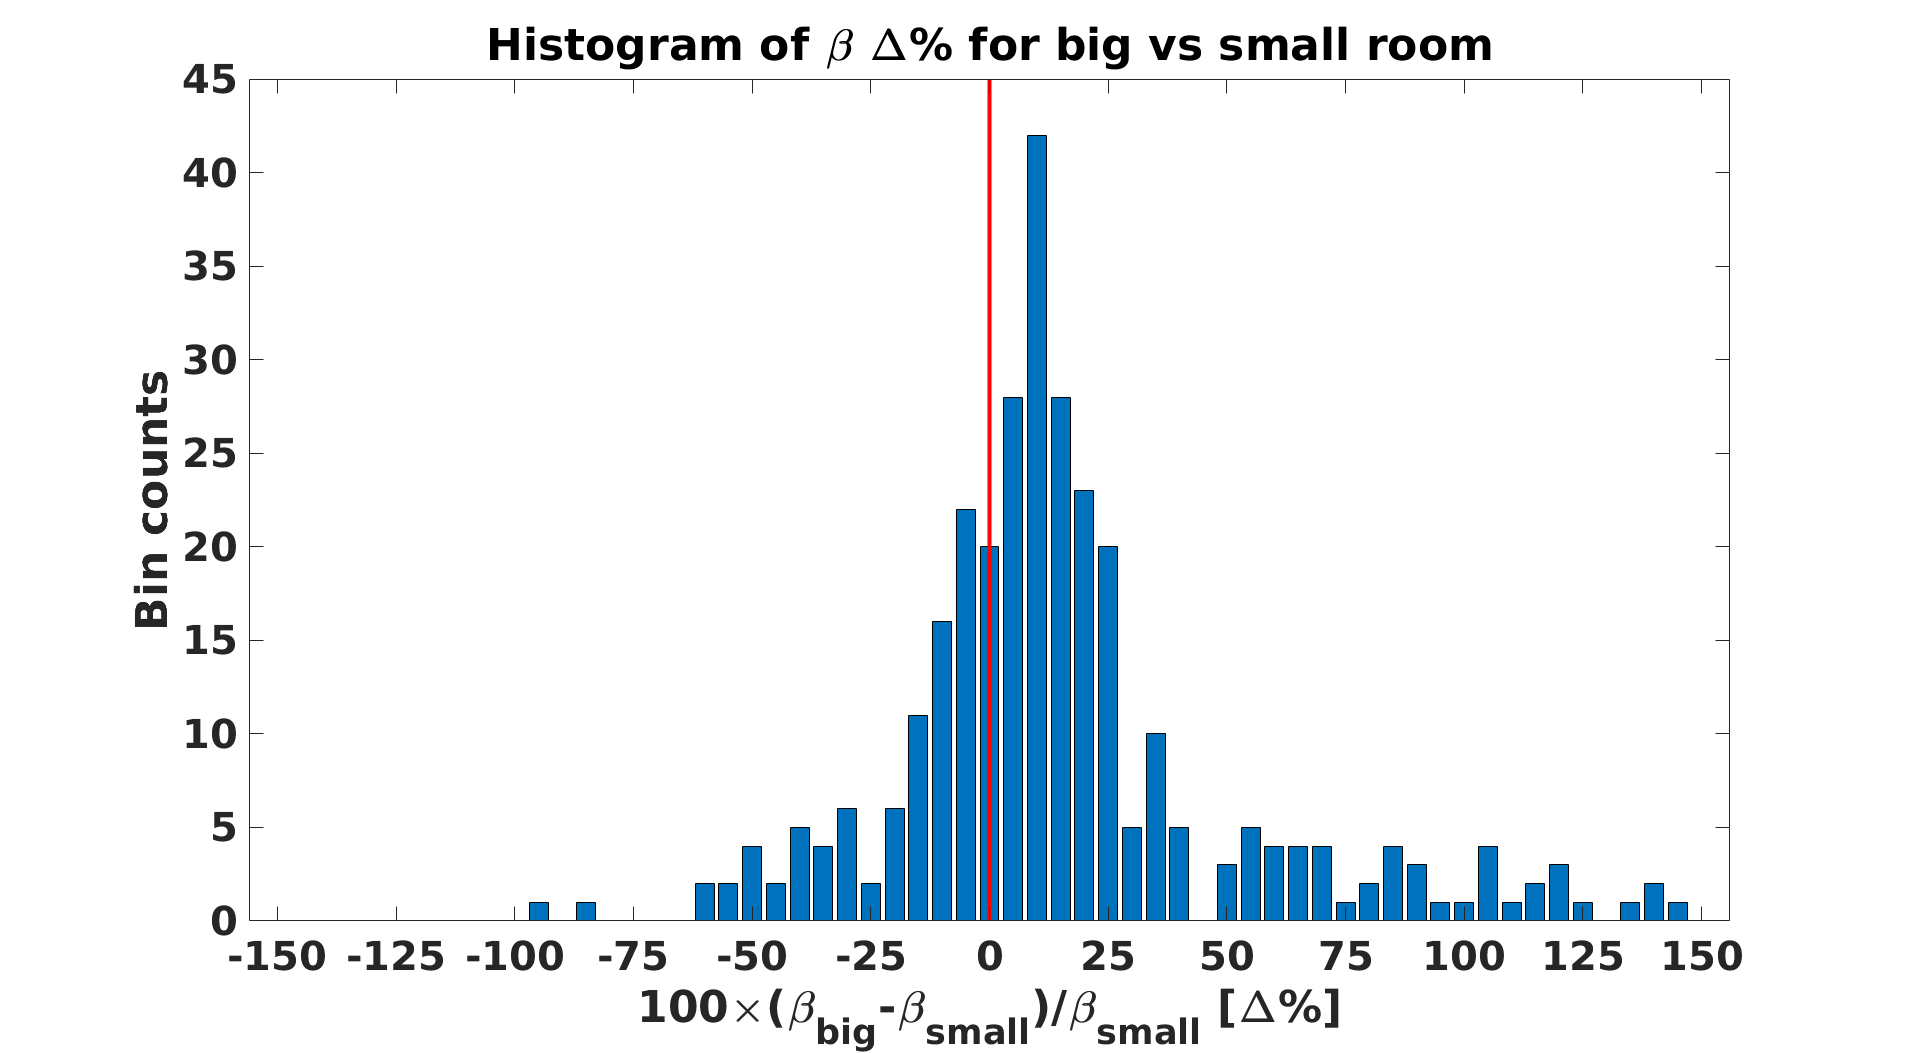

font_sz = 30;
font_label = 50;
beta_per_diff = reach(params,'per_big_small');
bin_width_per = 5;
spacing = 5;
edge_per = 150;
edges = [-edge_per:bin_width_per:edge_per];
hist_diff_per = histc(beta_per_diff(ix_good_data),edges);
figure('units','normalized','outerposition',[0 0 1 1]);
bar(hist_diff_per);
for jj = 1:numel(edges)
    x_labels{jj} = num2str(edges(jj),'%.0f');
end
h = vline(ceil(numel(edges)/2),'r');
h.LineWidth = 3;
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
xlabel('100\times(\beta_{big}-\beta_{small})/\beta_{small} [\Delta%]','FontSize',font_label,'FontWeight','bold');
ylabel('Bin counts','FontSize',font_label,'FontWeight','bold');
title(['Histogram of \beta \Delta% for big vs small room'],'FontSize',font_label,'FontWeight','bold');
set(gca,'FontName','Arial','FontSize',font_sz,'FontWeight','Bold');
set(gcf,'color','w');
file_name = [sfn_dir,'percentage_diff_histogram.jpg'];
export_fig(file_name);

Plot percentage the I/E ratio 

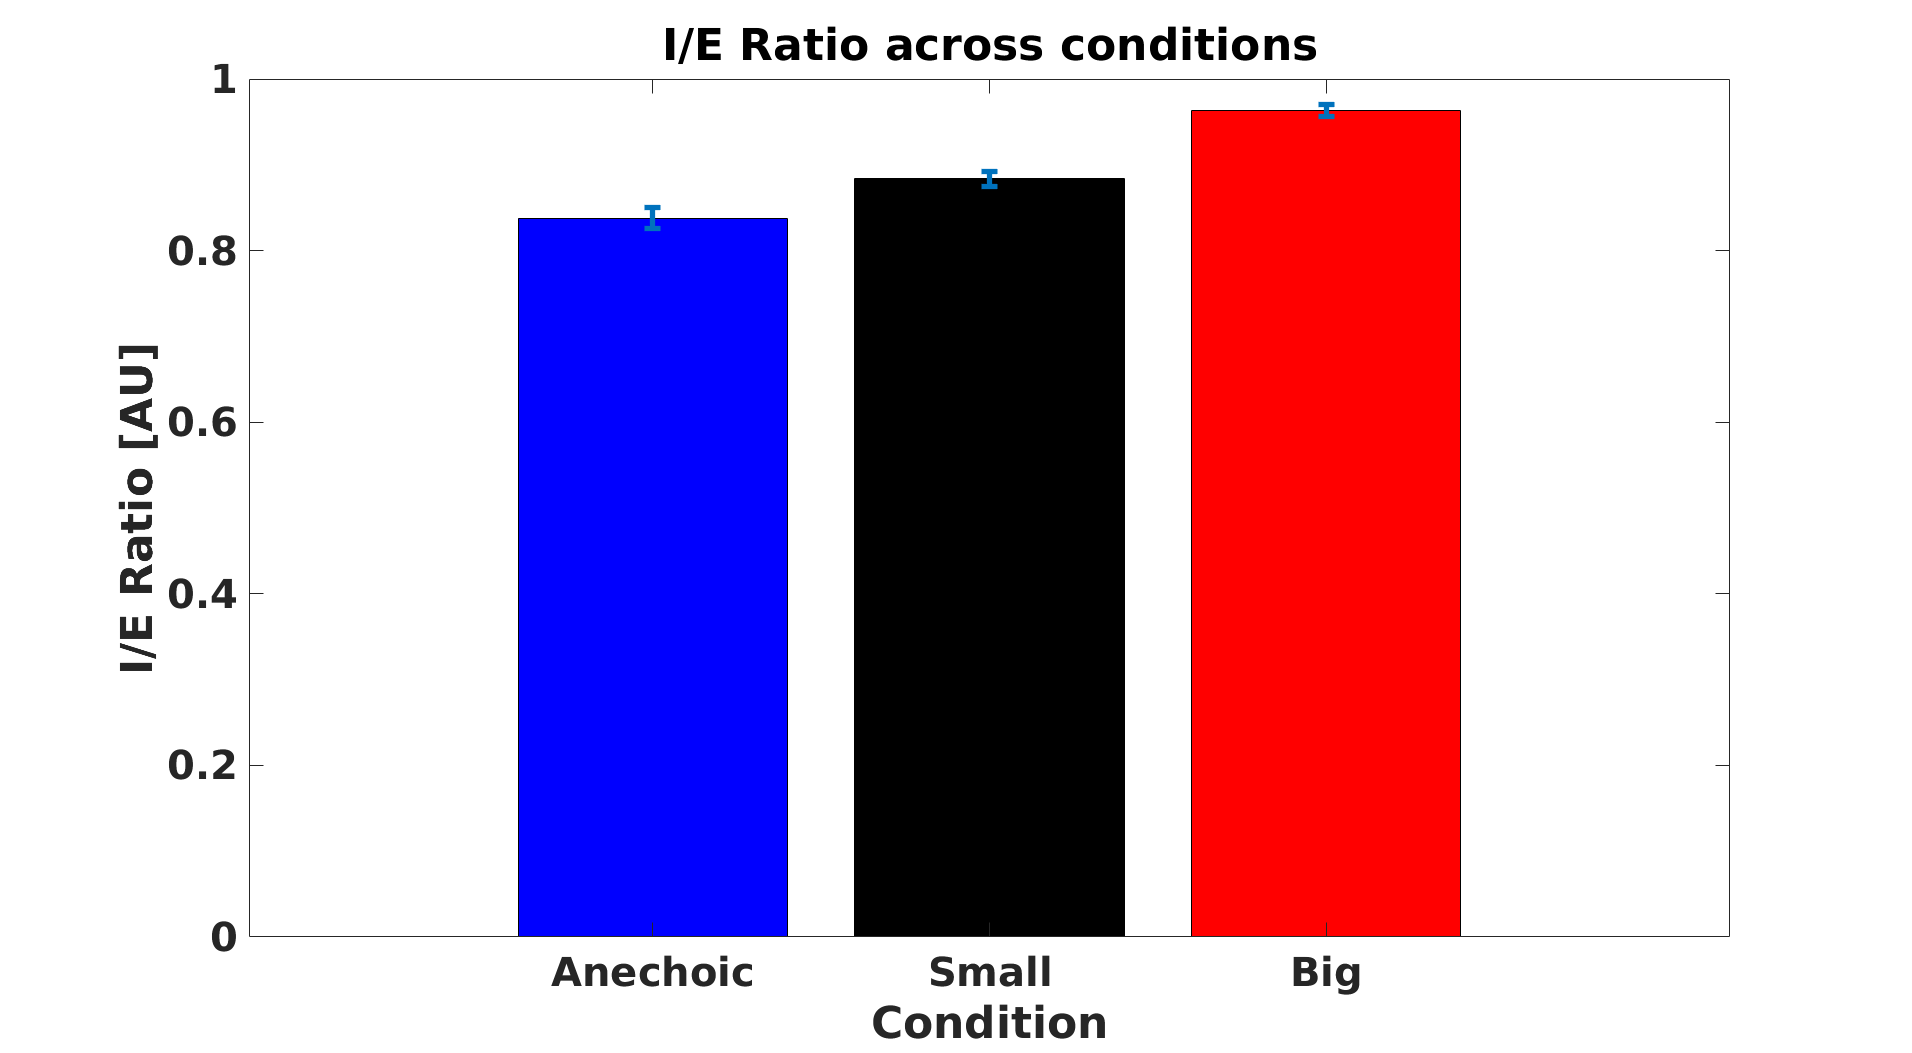

u_anech_ie = mean(ie_anech_all(ix_good_data));
u_reverb1_ie = mean(ie_reverb1_all(ix_good_data));
u_reverb2_ie = mean(ie_reverb2_all(ix_good_data));
sz = length(ie_anech_all(ix_good_data));
sqrt_n = sqrt(sz);
sem_anech_ie = std(ie_anech_all(ix_good_data))./sqrt_n;
sem_reverb1_ie = std(ie_reverb1_all(ix_good_data))./sqrt_n;
sem_reverb2_ie = std(ie_reverb2_all(ix_good_data))./sqrt_n;
figure('units','normalized','outerposition',[0 0 1 1]);
bar(1,u_anech_ie,'b');hold on;
bar(2,u_reverb1_ie,'k');
bar(3,u_reverb2_ie,'r');
errorbar([1 2 3],[u_anech_ie u_reverb1_ie u_reverb2_ie],[sem_anech_ie sem_reverb1_ie sem_reverb2_ie],'.','CapSize',12,'LineWidth',4);
xticks([1:3]);
xticklabels({'Anechoic','Small','Big'});
xlabel('Condition','FontSize',font_label,'FontWeight','bold');
ylabel('I/E Ratio [AU]','FontSize',font_label,'FontWeight','bold');
title(['I/E Ratio across conditions'],'FontSize',font_label,'FontWeight','bold');
set(gca,'FontName','Arial','FontSize',font_sz,'FontWeight','Bold');
set(gcf,'color','w');
file_name = [sfn_dir,'I_E_ratio.jpg'];
export_fig(file_name);

Plot the Inhibition

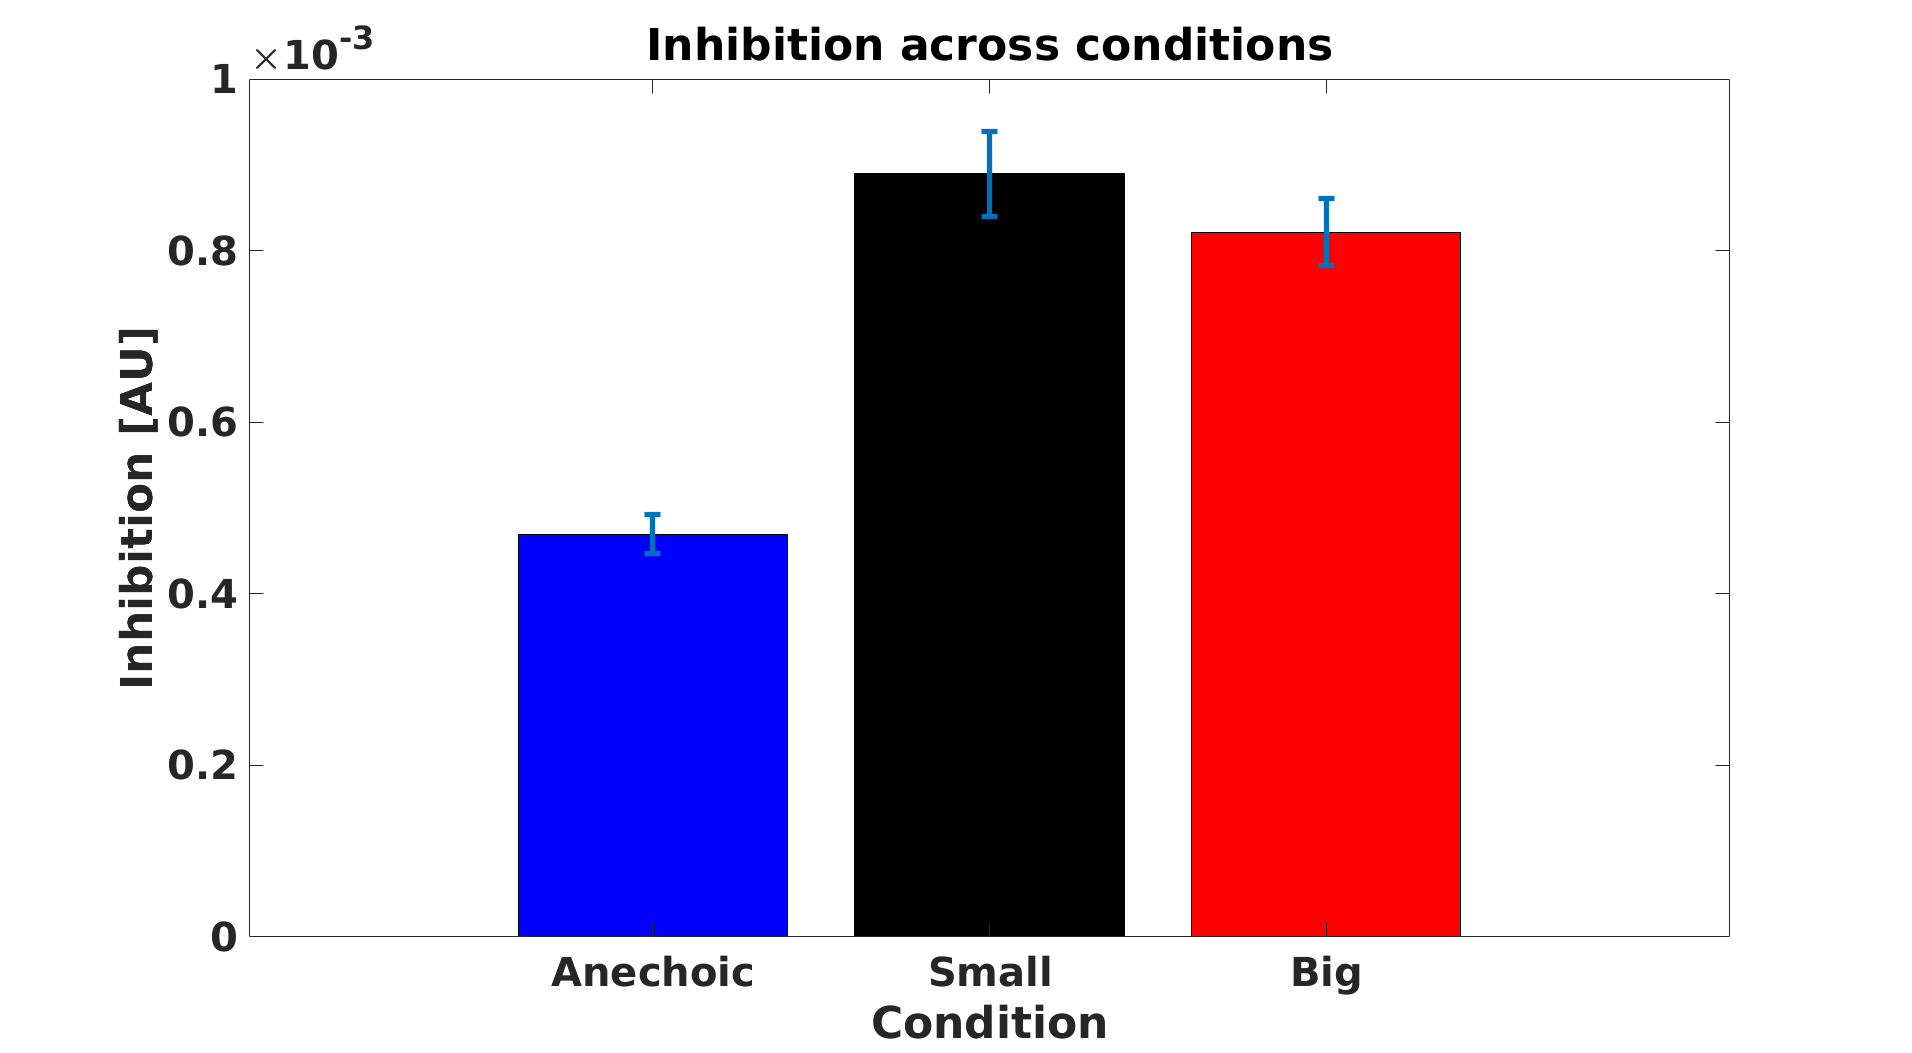

i_anech = i_anech_all(ix_good_data);
i_r1 = i_reverb1_all(ix_good_data);
i_r2 = i_reverb2_all(ix_good_data);
% mao = max(abs([i_anech(:);i_r1(:);i_r2(:)]));
% i_anech = i_anech./mao;
% i_r1 = i_r1./mao;
% i_r2 = i_r2./mao;
u_anech_i = mean(i_anech);
u_reverb1_i = mean(i_r1);
u_reverb2_i = mean(i_r2);
sz = length(i_anech);
sqrt_n = sqrt(sz);
sem_anech_i = std(i_anech)./sqrt_n;
sem_reverb1_i = std(i_r1)./sqrt_n;
sem_reverb2_i = std(i_r2)./sqrt_n;
figure('units','normalized','outerposition',[0 0 1 1]);
bar(1,u_anech_i,'b');hold on;
bar(2,u_reverb1_i,'k');
bar(3,u_reverb2_i,'r');
errorbar([1 2 3],[u_anech_i u_reverb1_i u_reverb2_i],[sem_anech_i sem_reverb1_i sem_reverb2_i],'.','CapSize',12,'LineWidth',4);
xticks([1:3]);
xticklabels({'Anechoic','Small','Big'});
xlabel('Condition','FontSize',font_label,'FontWeight','bold');
ylabel('Inhibition [AU]','FontSize',font_label,'FontWeight','bold');
title(['Inhibition across conditions'],'FontSize',font_label,'FontWeight','bold');
set(gca,'FontName','Arial','FontSize',font_sz,'FontWeight','Bold');
set(gcf,'color','w');
file_name = [sfn_dir,'Inhibition_across_conditions.jpg'];
export_fig(file_name);

Plot percentage diff histogram (small vs anech)

% per_small_anech = small_beta - anech_beta;
% per_small_anech = per_small_anech(ix_good_data);
% bin_width_per = 5;
% spacing = 5;
% edge_per = 100;
% edges = [-edge_per:bin_width_per:edge_per];
% hist_diff_small_anech = histc(per_small_anech,edges);
% figure('units','normalized','outerposition',[0 0 1 1]);
% bar(hist_diff_small_anech);
% for jj = 1:numel(edges)
%     x_labels{jj} = num2str(edges(jj),'%.0f');
% end
% vline(numel(edges)/2,'r');
% xticks([1:spacing:numel(edges)]);
% xticklabels(x_labels([1:spacing:numel(edges)]));
% xlabel('100*(\beta_{small}-\beta_{anech}/\beta_{anech} [%]');
% ylabel('Frequency','FontSize',16);
% title(['Histogram of \beta percentage change for ',type,' neurons']);
% set(0,'defaultAxesFontSize',16);


Plot percentage diff histogram (small vs anech)

% bin_width_per = 10;
% spacing = 10;
% edge_per = 450;
% edges = [0:bin_width_per:edge_per];
% hist_anech = histc(anech_beta(ix_good_data),edges);
% hist_reverb1 = histc(small_beta(ix_good_data),edges);
% hist_reverb2 = histc(big_beta(ix_good_data),edges);
% figure('units','normalized','outerposition',[0 0 1 1]);
% for jj = 1:numel(edges)
%     x_labels{jj} = num2str(edges(jj),'%.0f');
% end
% xticks([1:spacing:numel(edges)]);
% xticklabels(x_labels([1:spacing:numel(edges)]));
% subplot(3,1,1);
% bar(edges,hist_anech,'histc','b');
% subplot(3,1,2);
% bar(edges,hist_reverb1,'histc','k');
% 
% subplot(3,1,3);
% bar(edges,hist_reverb2,'histc','r');
% 
% % edges = [-192.5:5:192.5];
% % hist_diff = histc(small_beta(ix_good_data)-anech_beta(ix_good_data),edges);
% % bar(edges,hist_diff,'histc');
% % for jj = 1:numel(edges)
% %     x_labels{jj} = num2str(edges(jj),'%.0f');
% % end
% % vline(numel(edges)/2,'r');
% % xticks([1:spacing:numel(edges)]);
% % xticklabels(x_labels([1:spacing:numel(edges)]));
% xlabel('\beta [ms]');
% ylabel('Frequency','FontSize',16);
% title(['Histogram of \beta for the three conditions for ',type,' neurons']);
% set(0,'defaultAxesFontSize',16);

Plot beta as a finction of B

% figure('units','normalized','outerposition',[0 0 1 1]);
% scatter(abs(B_anech_all),anech_beta,'b');hold on;
% scatter(abs(B_reverb1_all),small_beta,'k');
% scatter(abs(B_reverb2_all),big_beta,'r');
% xlabel('B const [AU]');
% ylabel('\beta const [ms]');
% title(['Inhibition across conditions for ',type,' neurons']);
% set(0,'defaultAxesFontSize',16);
